# `SHeatmap (special heatmap)`

`Zhaoxu Liu / slandarer (2023). special heatmap (https://www.mathworks.com/matlabcentral/fileexchange/125520-special-heatmap), MATLAB Central File Exchange. 检索来源 2023/3/1.`

## `1 Basic use (基础使用)`

### `1.1 Draw positive heatmap (非负矩阵)`

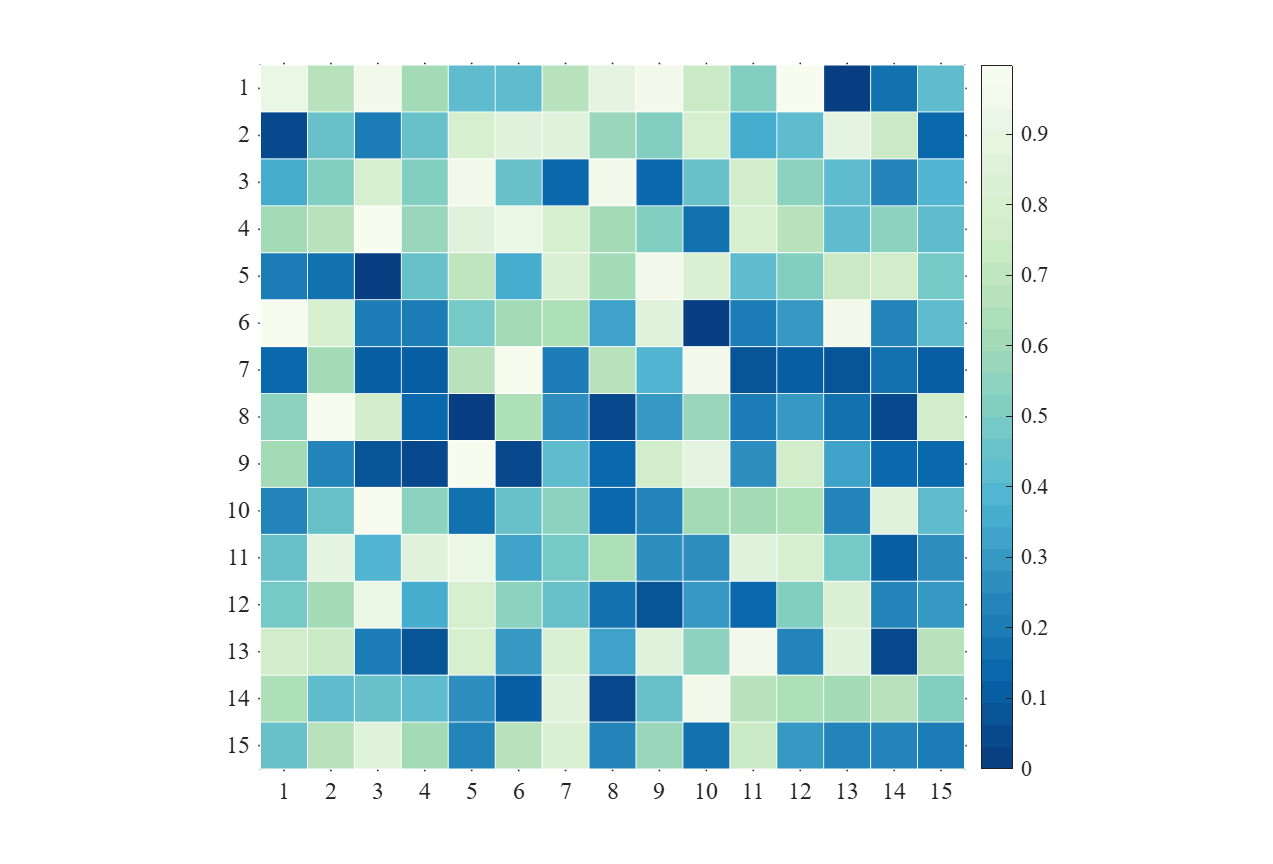

figure()
Data = rand(15, 15);
SHM1 = SHeatmap(Data, 'Format','sq');
SHM1.draw();

### `1.2 Contains negative numbers (绘制有负数热图)`

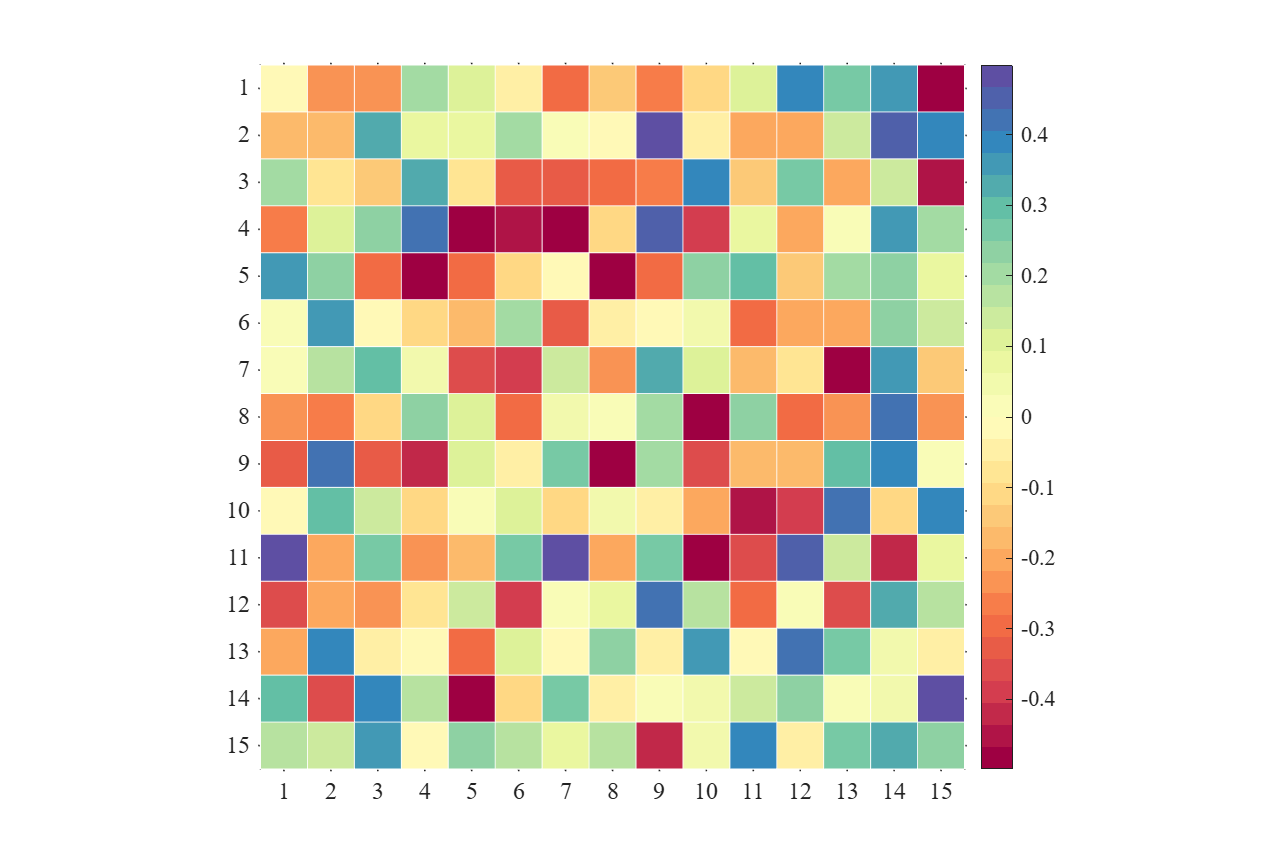

figure()
Data = rand(15,15) - .5;
SHM2 = SHeatmap(Data, 'Format','sq');
SHM2.draw();

### `1.3 Draw heatmaps of different sizes (绘制不同大小热图)`

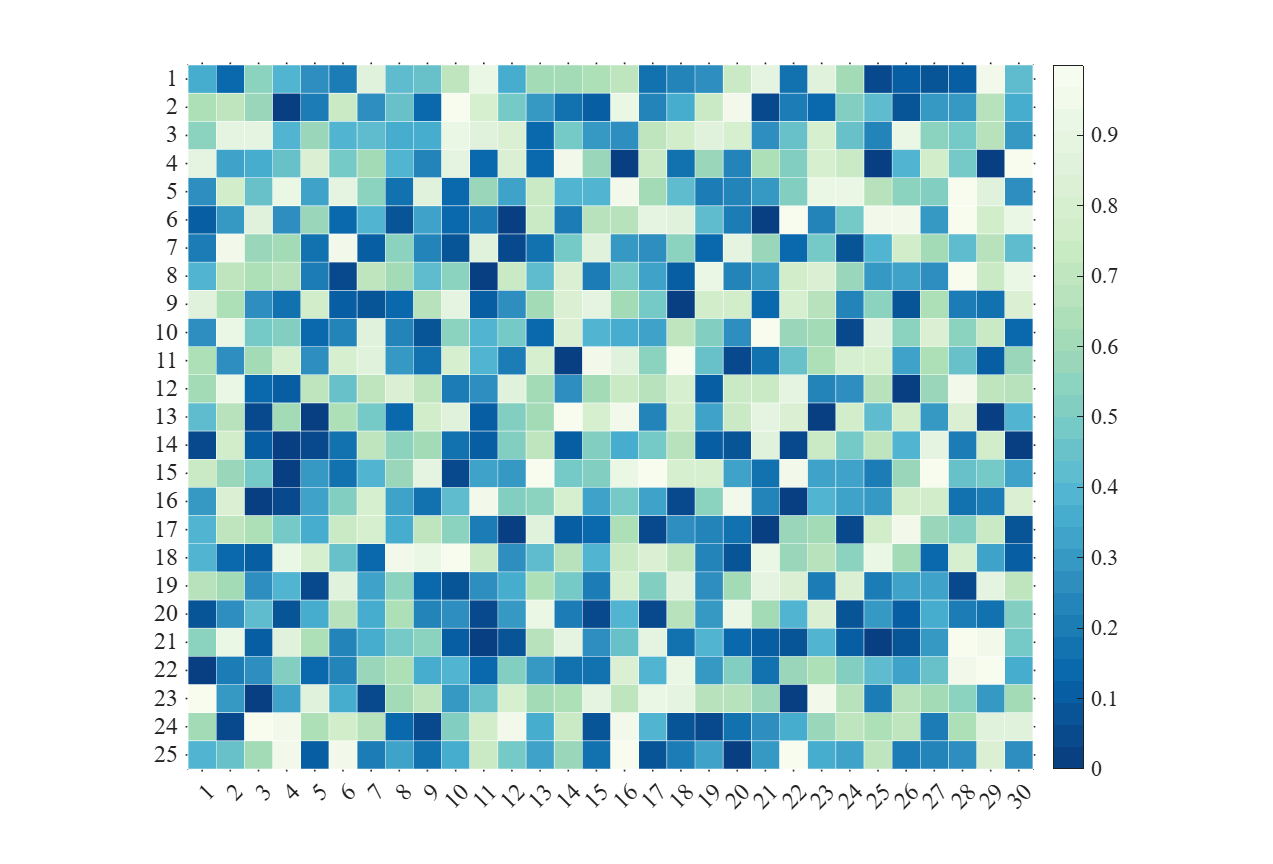

figure()
Data = rand(25, 30);
SHM3 = SHeatmap(Data, 'Format','sq');
SHM3.draw();

### `1.4 Adjust the colorbar Location (调整colorbar位置)`

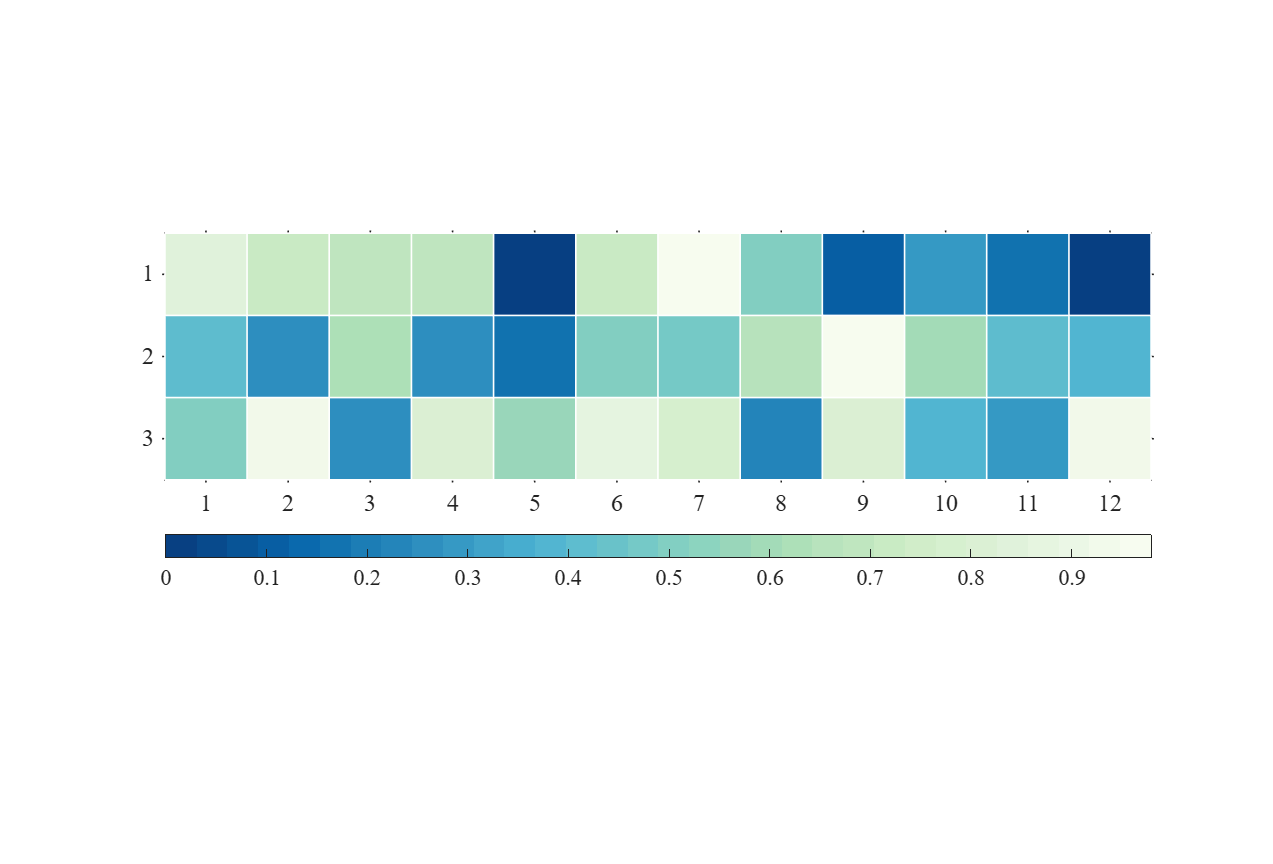

figure()
Data = rand(3,12);
SHM4 = SHeatmap(Data, 'Format','sq');
SHM4.draw();
CB = colorbar;
CB.Location = 'southoutside';

### `1.5 Draw heatmap with NaN (绘制有 NaN 热图)`

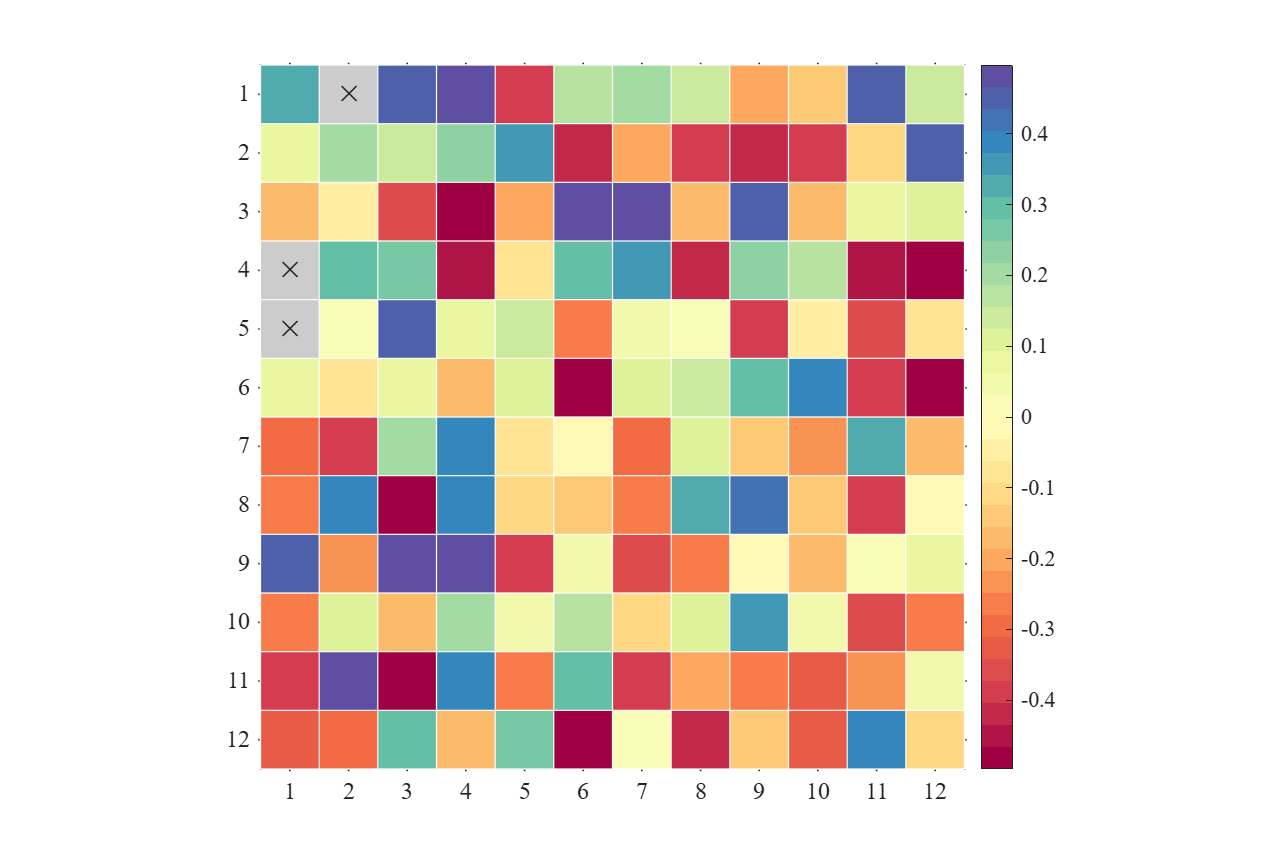

figure()
Data = rand(12, 12) - .5;
Data([4, 5, 13]) = nan;
SHM5 = SHeatmap(Data, 'Format','sq');
SHM5.draw();

### `1.6 Draw heatmap with value text (绘制有文本热图)`

`Use the ``obj.setText()` `method to display value text:`

`使用 ``obj.setText()` `方法显示文字：`

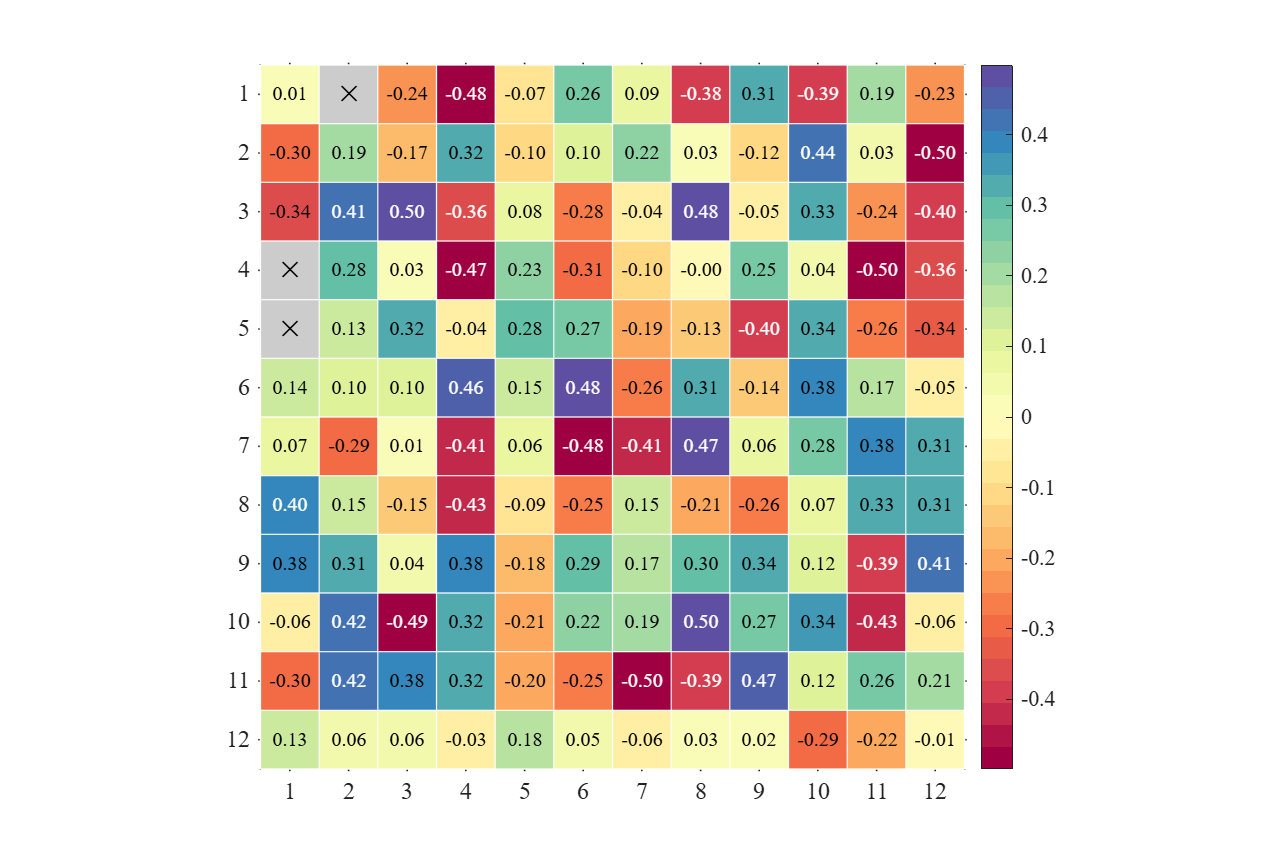

figure()
Data = rand(12, 12) - .5;
Data([4, 5, 13]) = nan;
SHM6 = SHeatmap(Data, 'Format','sq');
SHM6.draw();
SHM6.setText();

### `1.7 Draw heatmap with labels (绘制带标签热图)`

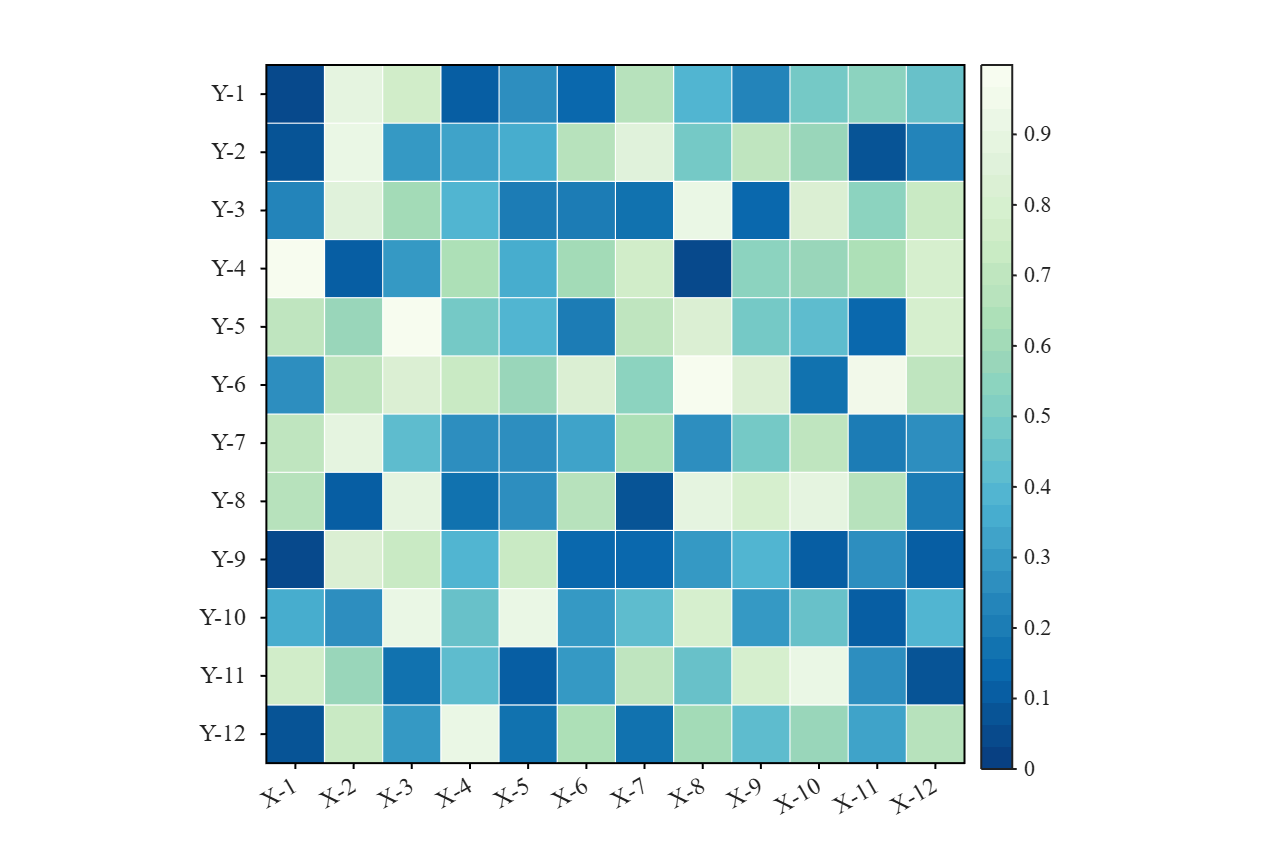

figure()
Data = rand(12, 12);
SHM7 = SHeatmap(Data, 'Format','sq');
SHM7.ColName = {'X-1','X-2','X-3','X-4','X-5','X-6','X-7','X-8','X-9','X-10','X-11','X-12'};
SHM7.RowName = {'Y-1','Y-2','Y-3','Y-4','Y-5','Y-6','Y-7','Y-8','Y-9','Y-10','Y-11','Y-12'};
SHM7.draw(); 
SHM7.setFrame()

## `2 Various Format of heatmaps (各类型热图绘制)`

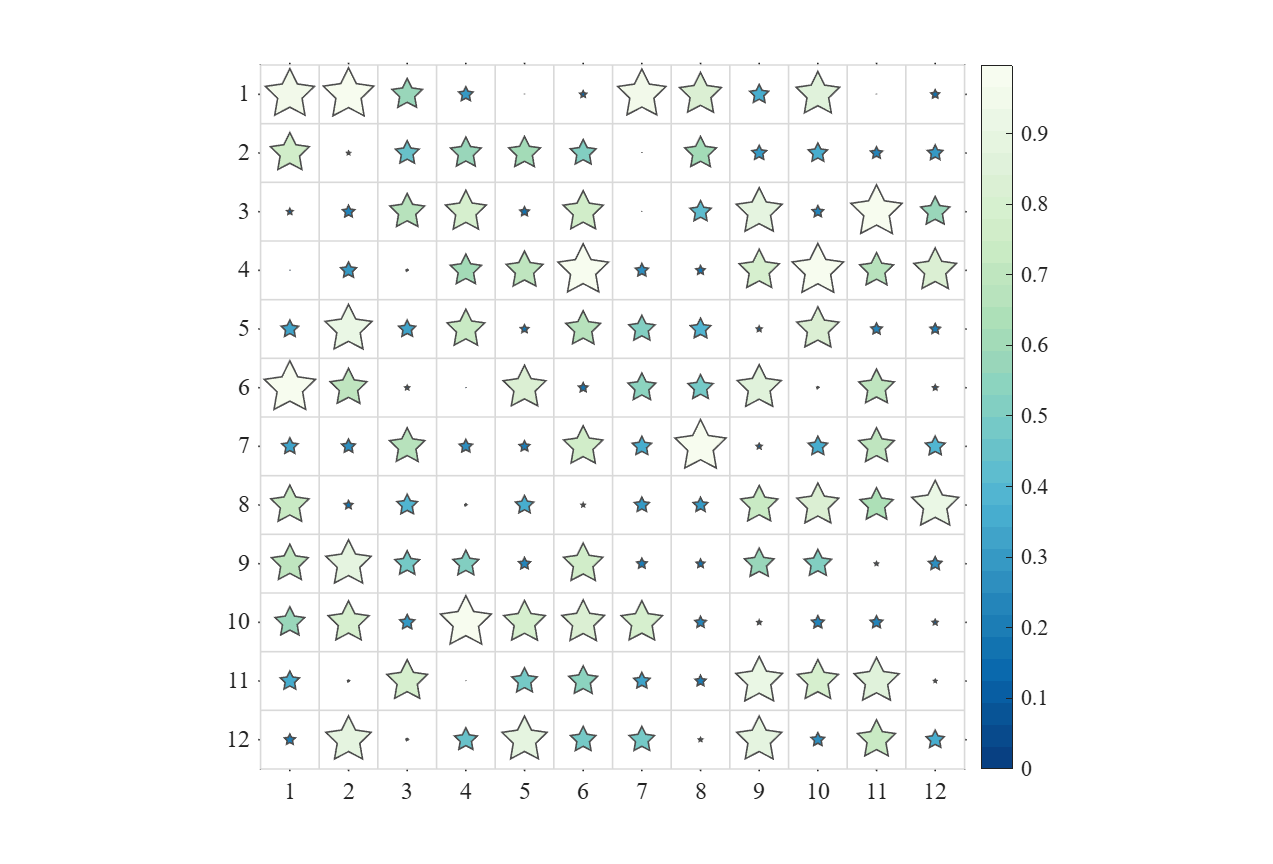

% 'sq'          : square (default)          : 方形(默认)
% 'pie'         : pie chart                 : 饼图
% 'donut'       ：donut chart               : 环形饼图(甜甜圈图)
% 'circ'        : circular                  : 圆形
% 'bcirc'       : circle with box           : 有边框的圆形
% 'oval'        : oval                      : 椭圆形
% 'hex'         : hexagon                   ：六边形
% 'star'        : star                      : 五角星
% 'trill'(tril) : lower left triangle       : 下三角
% 'triur'(triu) : upper right triangle      : 上三角
% 'trilr'       : lower right triangle      : 右下三角
% 'triul'       : upper left triangle       : 左上三角
% 'asq'         : auto-size square          ：自带调整大小的方形
% 'acirc'       : auto-size circular        ：自带调整大小的圆形

A = rand(12, 12);
B = rand(12, 12) - .5;


% Draw positive heatmap (绘制纯正数热图)
figure();
SHM_A = SHeatmap(A, 'Format','star');
SHM_A.draw();

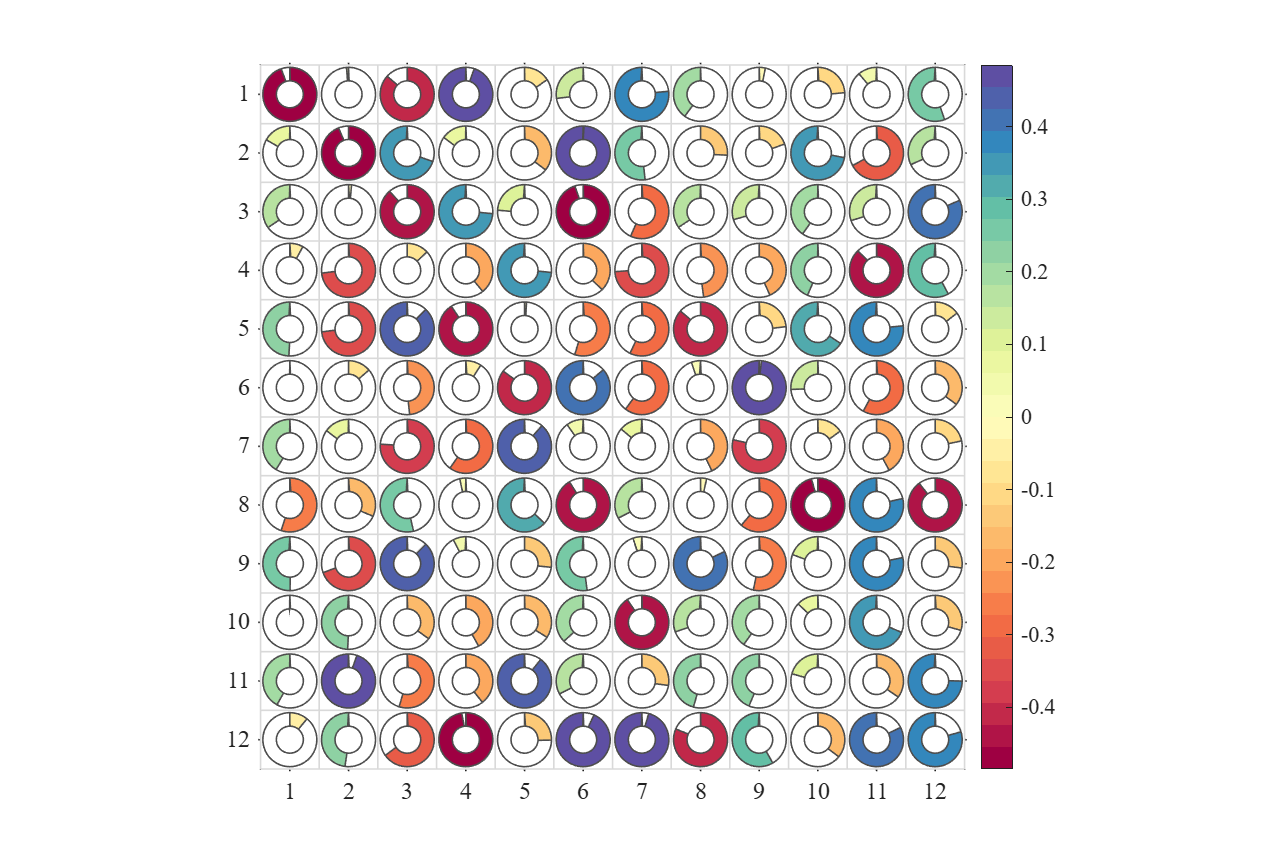

% Draw heat map with negative number (绘制含负数热图)
figure();
SHM_B = SHeatmap(B, 'Format','donut');
SHM_B.draw();

### `2.2 Custom shape and auto-size custom shape (自定义形状)`

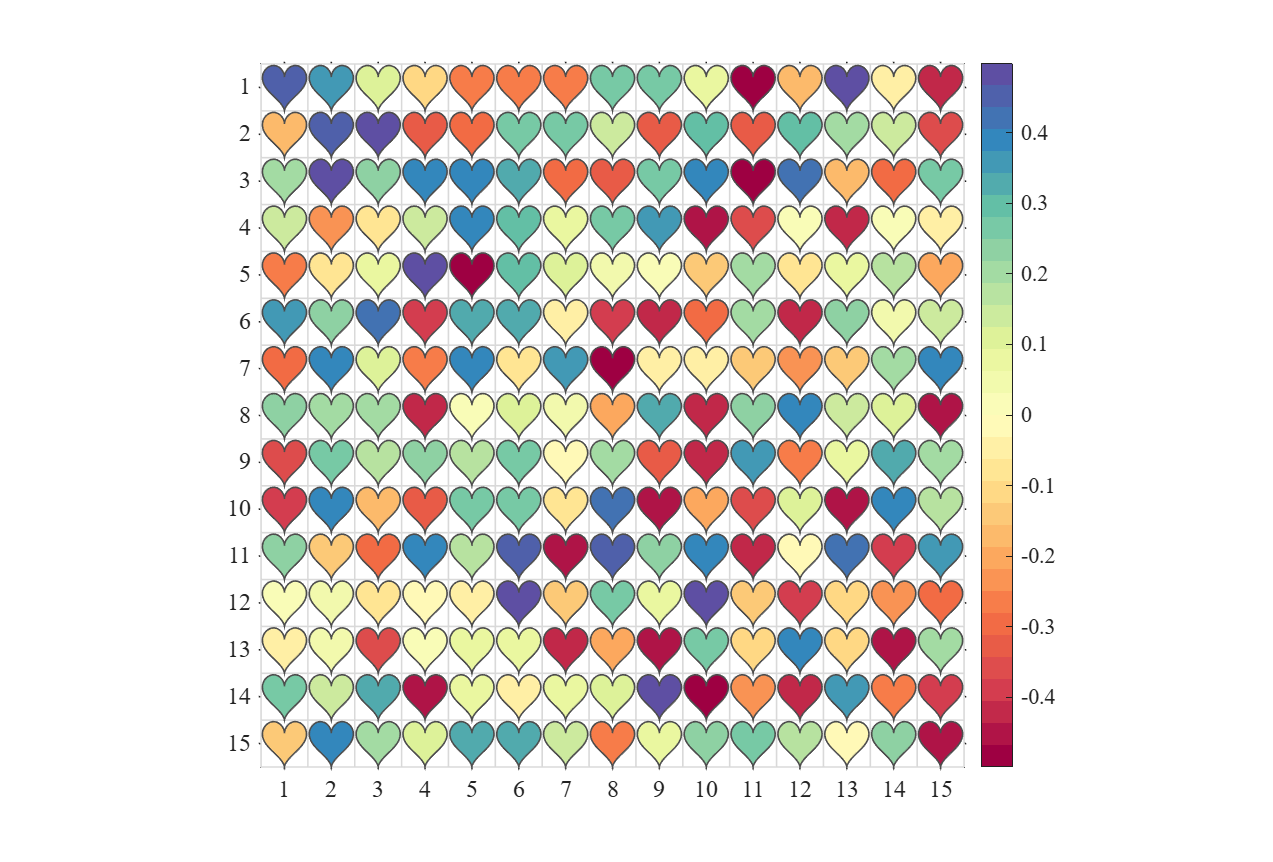

% The shape need to be in range in X:[-.5,.5], Y:[-.5,.5]; 
% The 'SData' need to be set.

% heart shape
t = linspace(0, 2*pi, 200);
x = 16*sin(t).^3./34;
y = (13*cos(t) - 5*cos(2*t) - 2*cos(3*t) - cos(4*t) + 2.1)./30;
SData = [x; y];

% custom shape
figure()
Data = rand(15, 15) - .5;
SHM1 = SHeatmap(Data, 'Format','cust', 'SData',SData);
SHM1.draw();

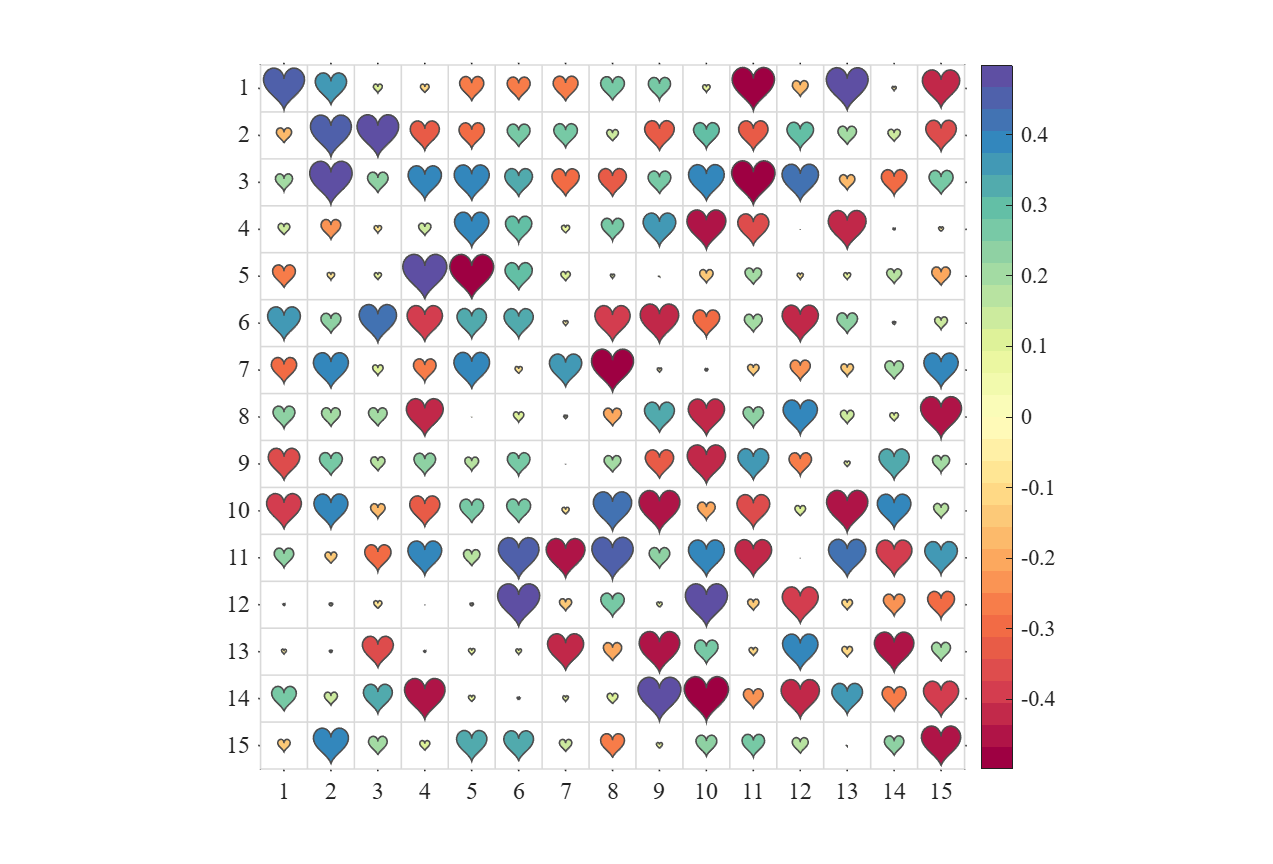

% auto-size custom shape
figure()
SHM2 = SHeatmap(Data, 'Format','acust', 'SData',SData);
SHM2.draw();

## `3 Adjust colormap (调整 colormap)`

### `3.1 Adjust clim (调整 clim)`

`Use function ``clim()`` or ``caxis()`` to set the CLim`

`使用 ``clim()`` 或者 ``caxis()`` 调整颜色映射范围`

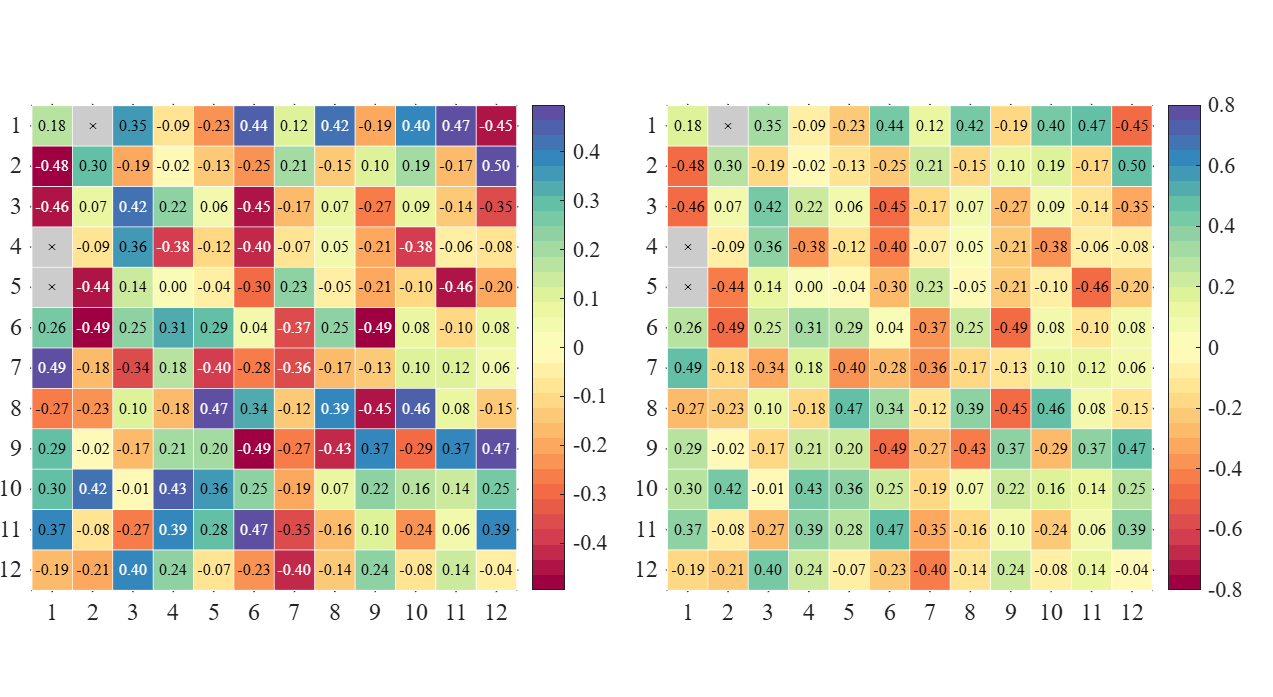

fig = figure('Units','normalized', 'Position',[.1,.1,.8,.7]);

% random data
Data = rand(12, 12) - .5; Data([4, 5, 13]) = nan;

% subplot1
ax1 = axes('Parent',fig, 'Position',[ 1/40, 0, 9/20, 1]);
SHM_ax1 = SHeatmap(Data, 'Format','sq', 'Parent',ax1).draw();
SHM_ax1.setText('FontSize',8);

% subplot2 adjust clim
ax2 = axes('Parent',fig, 'Position',[21/40, 0, 9/20, 1]);
SHM_ax2 = SHeatmap(Data, 'Format','sq', 'Parent',ax2).draw();
clim([-.8, .8])
SHM_ax2.setText('FontSize',8);

### `3.2 Use the built-in colormap in MATLAB (使用 MATLAB 自带 colormap)`

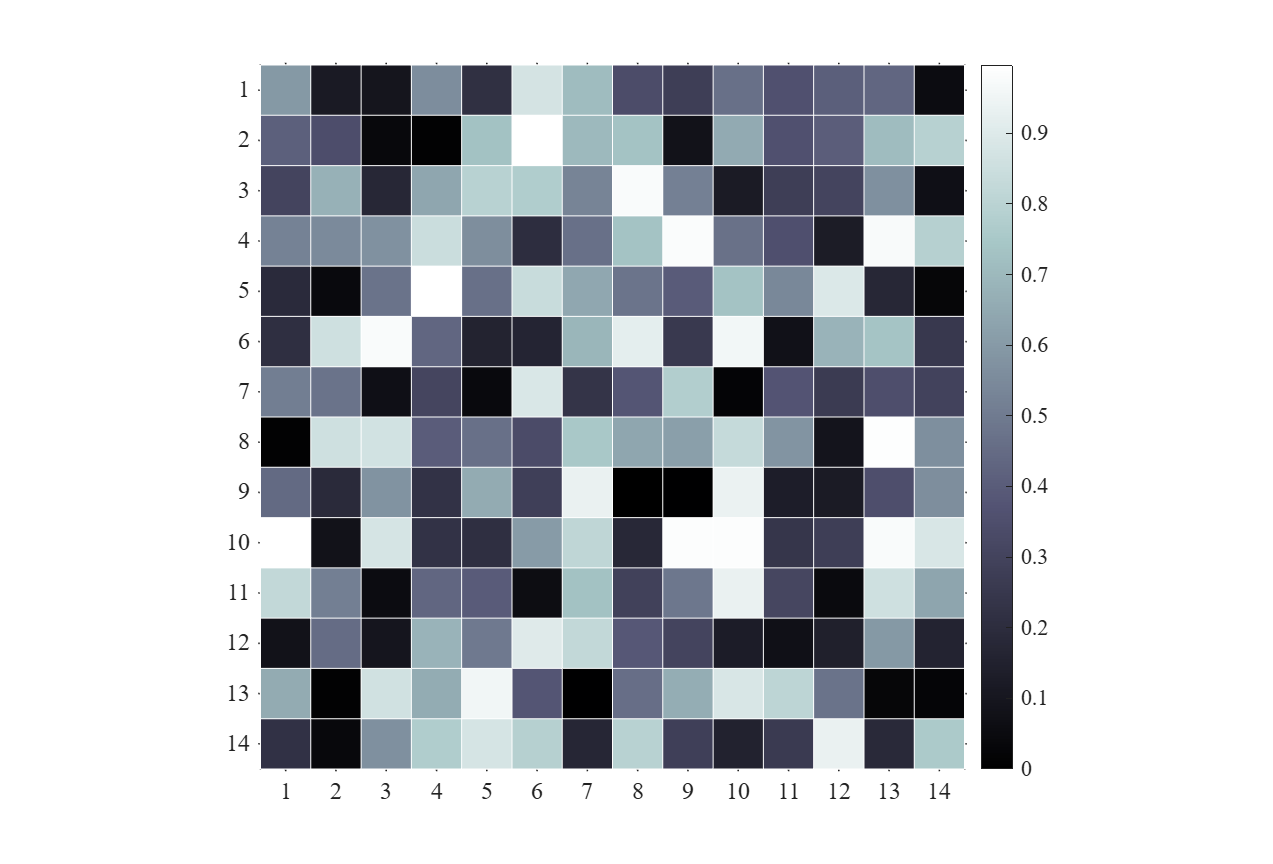

figure()
Data = rand(14, 14);
SHM_Bone = SHeatmap(Data, 'Format','sq');
SHM_Bone.draw();
colormap(bone)

### `3.3 slanCM (slanCM colormap)`

`Zhaoxu Liu / slandarer (2023). 200 colormap (https://www.mathworks.com/matlabcentral/fileexchange/120088-200-colormap), MATLAB Central File Exchange. 检索来源 2023/3/15.`

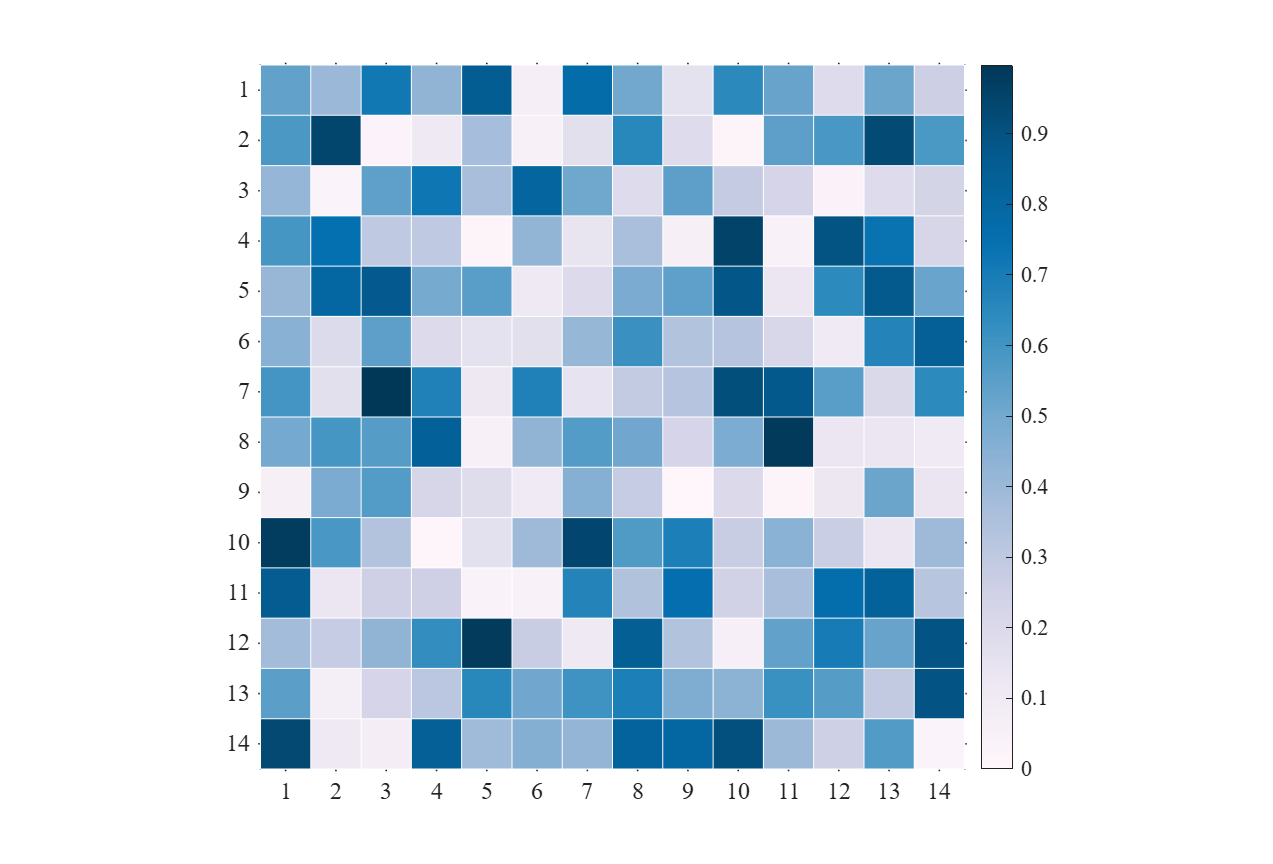

% 单向 colormap 或离散 colormap
for i = 20 % [20, 21, 61, 177]
    figure()
    Data = rand(14, 14);
    SHM_slan = SHeatmap(Data, 'Format','sq');
    SHM_slan.draw();
    colormap(slanCM(i))
end

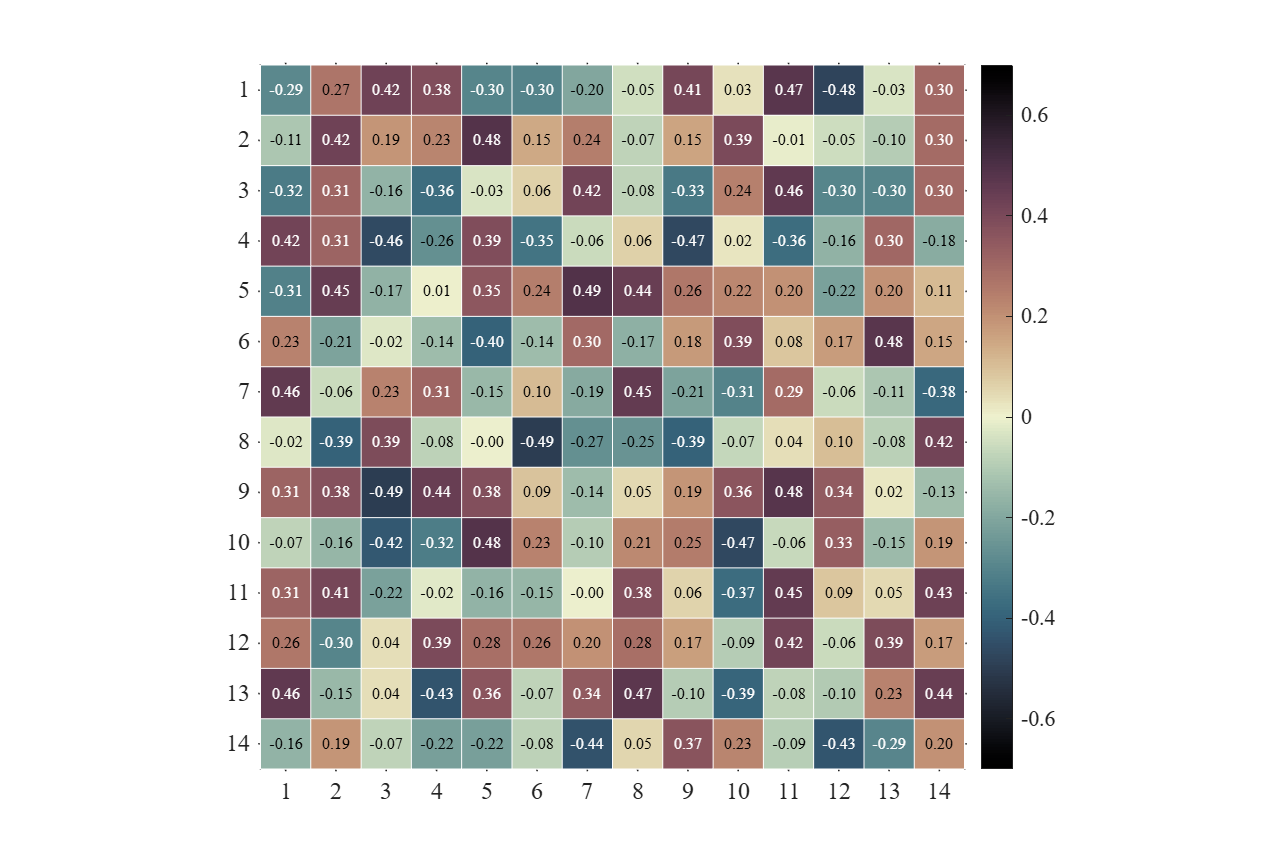

% 双向 colormap (Diverging colormap)
for i = 141 % [141, 136, 134]
    figure()
    Data = rand(14, 14) - .5;
    SHM_slan = SHeatmap(Data, 'Format','sq');
    SHM_slan.draw();
    clim([-.7, .7])
    colormap(slanCM(i))
    SHM_slan.setText('FontSize',8);
end

## `4 Overall decoration (整体修饰)`

- `obj.setBox(___)   ：修饰边框`

- `obj.setPatch(___)  ：修饰图形`

- `obj.setText(___)   ：修饰文本`

- `obj.setFrame(___) : 修饰外轮廓`

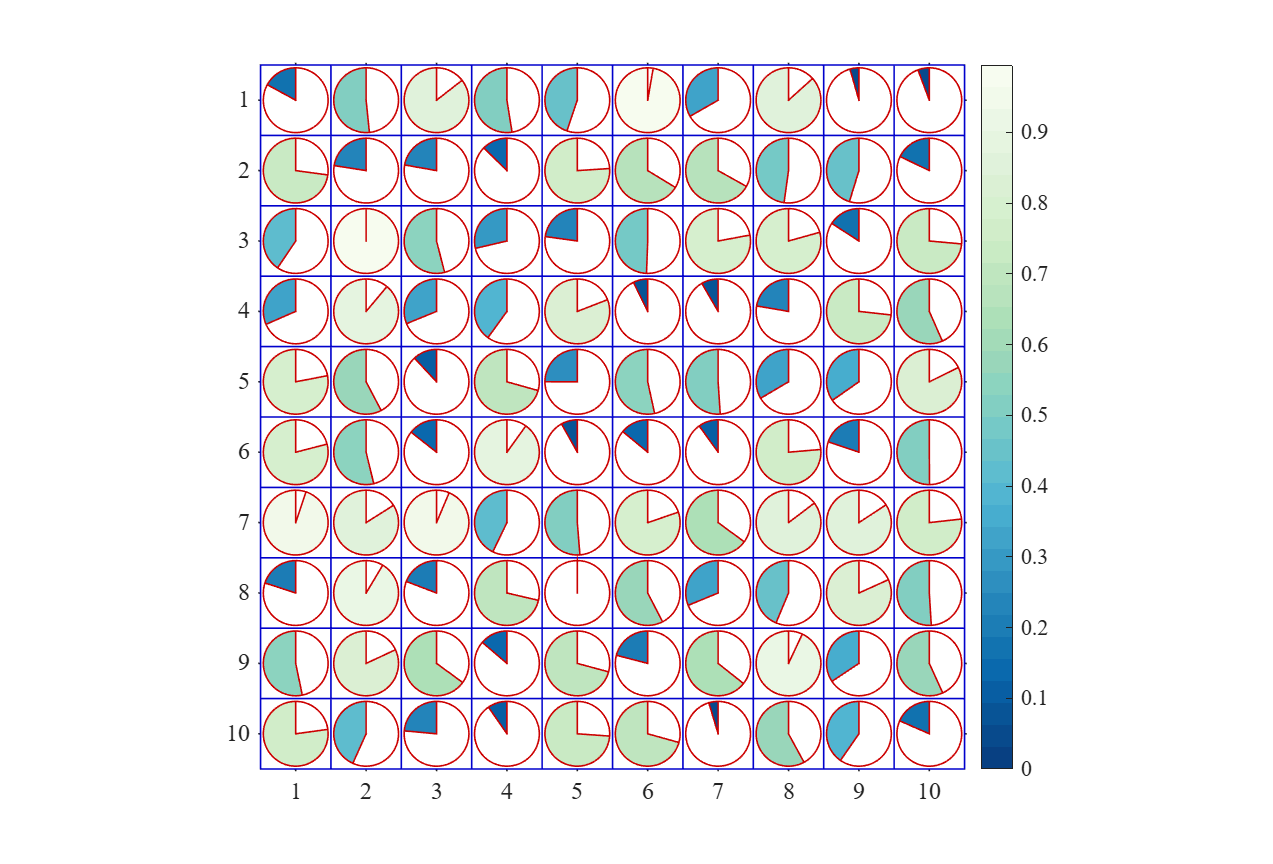

figure()
Data = rand(10, 10);

SHM = SHeatmap(Data, 'Format','pie');
SHM.draw(); 
% The container box border is set to blue (容器边框设置为蓝色)
% The drawing border is set to red (图形边框设置为红色)
SHM.setBox('Color',[0,0,.8])
SHM.setPatch('EdgeColor',[.8,0,0])

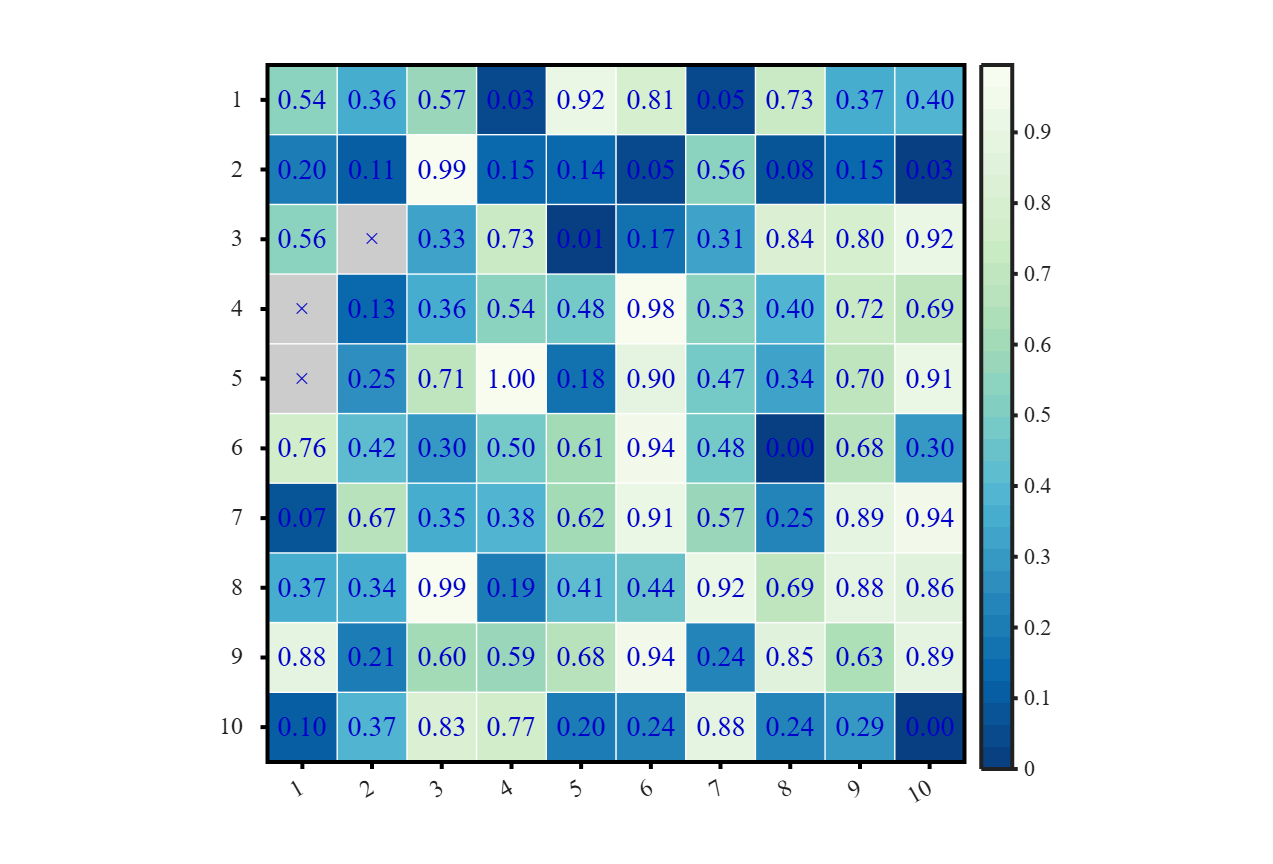

figure()
Data = rand(10, 10); Data([4, 5, 13]) = nan;

SHM = SHeatmap(Data, 'Format','sq');
SHM.draw(); 
% Set the text to blue and modify the font size (设置文本为蓝色并修改字号)
SHM.setText('Color',[0,0,.8], 'FontSize',14)
SHM.setFrame('LineWidth',2)

## `5 Partial decoration (局部修饰)`

- `obj.setText(m, n, ___)`

- `setPatch(m, n, ___)`

`Set the attributes of the object in row m and column n: for example, change the text with a value greater than 0.9 into an asterisk, frame it in red, and adapt the color at NaN.`

`设置第 m 行 n 列对象的属性：举个例子，把数值大于 0.9 部分文字变为星号，并用红色框框起来，并修改 NaN 处颜色。`

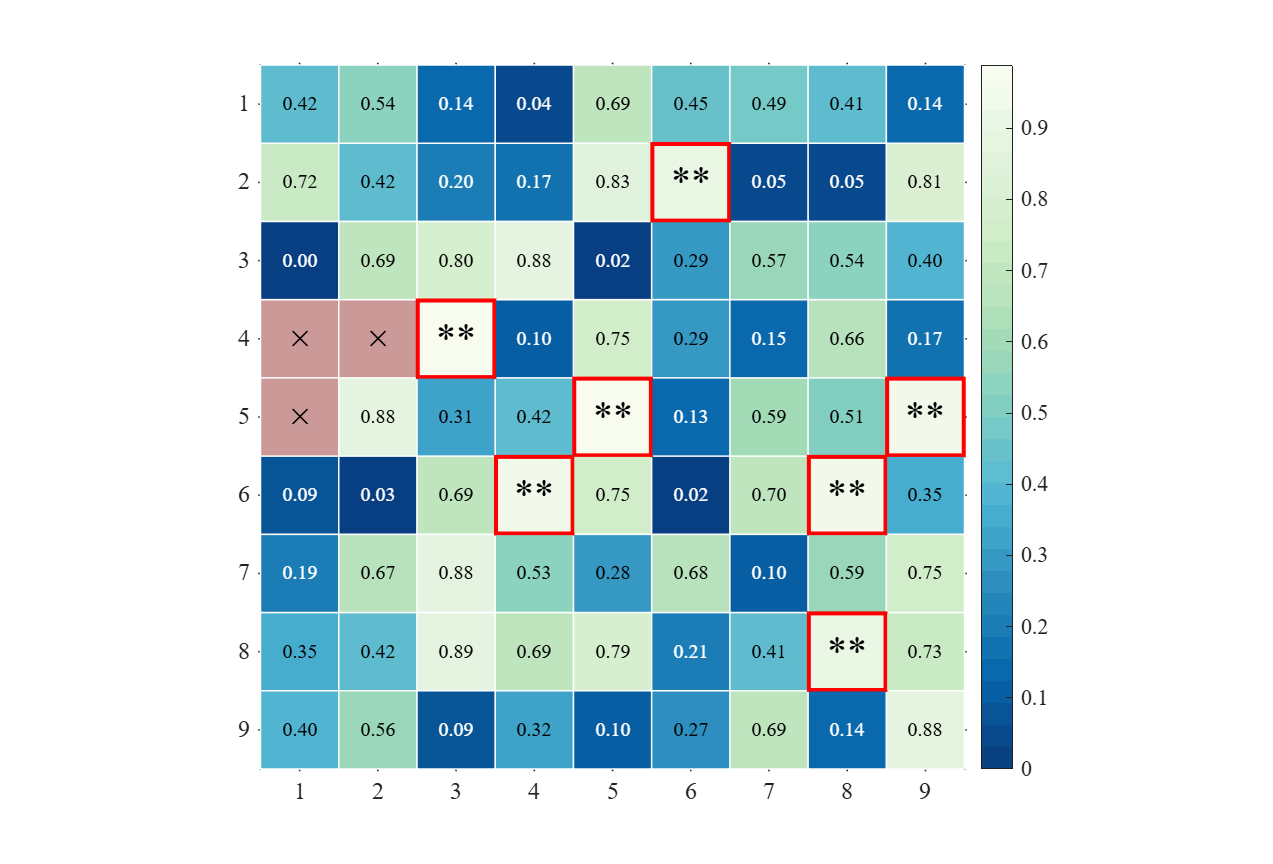

rng(1)
figure()
Data = rand(9, 9); Data([4, 5, 13]) = nan;

SHM = SHeatmap(Data, 'Format','sq');
SHM.draw();

% Show Text (显示文本)
SHM.setText(); 

for i = 1:size(Data,1)
    for j = 1:size(Data,2)
        if Data(i, j) >= .9
            SHM.setText(i, j, 'String','**', 'FontSize',20)         % Modify color of patches where Data >= 0.9 (修改 >= 0.9 方块颜色)
            SHM.setPatch(i, j, 'EdgeColor',[1,0,0], 'LineWidth',2)  % Set text where Data >= 0.9 to '**' (修改 >= 0.9 方块文本为**)
        end
        if isnan(Data(i, j))
            SHM.setPatch(i, j, 'FaceColor',[.8,.6,.6])              % Modify color of NaN patches (修改 NaN 处颜色)
        end
    end
end

`Using logical values is more convenient.`

`使用逻辑值会更简单:`

rng(1)
figure()
Data = rand(9, 9); Data([4,5,13]) = nan;

SHM = SHeatmap(Data, 'Format','sq');
SHM.draw();
SHM.setText()

SHM.setText(Data >= .9, 'String','**', 'FontSize',20)         % Modify color of patches where Data >= 0.9 (修改 >= 0.9 方块颜色)
SHM.setPatch(Data >= .9, 'EdgeColor',[1,0,0], 'LineWidth',2)  % Set text where Data >= 0.9 to '**' (修改 >= 0.9 方块文本为**)
SHM.setPatch(isnan(Data), 'FaceColor',[.8,.6,.6])             % Modify color of NaN patches (修改 NaN 处颜色)

## `6 Set to upper triangle or lower triangle (设置为上三角或下三角)`

### `6.1 upper triangle or lower triangle (上下三角格式)`

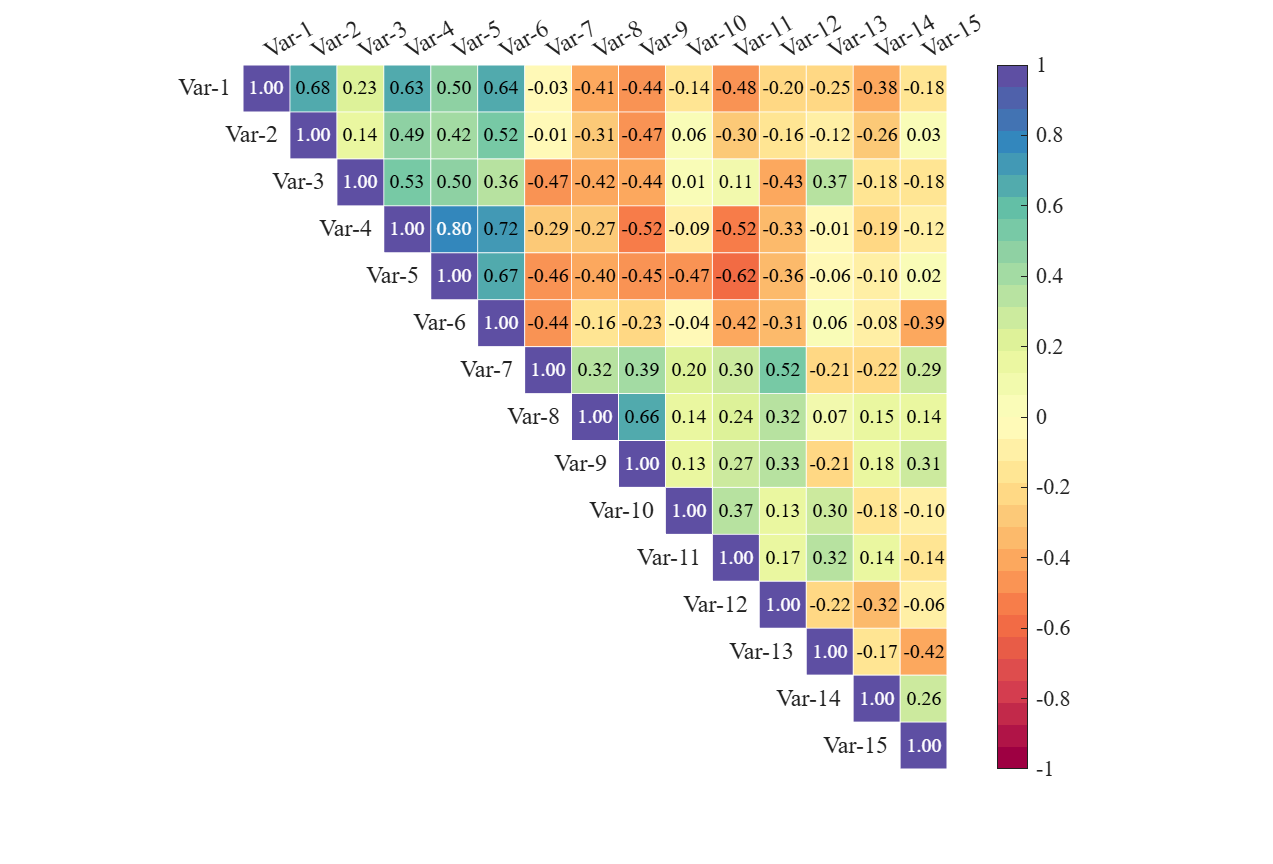

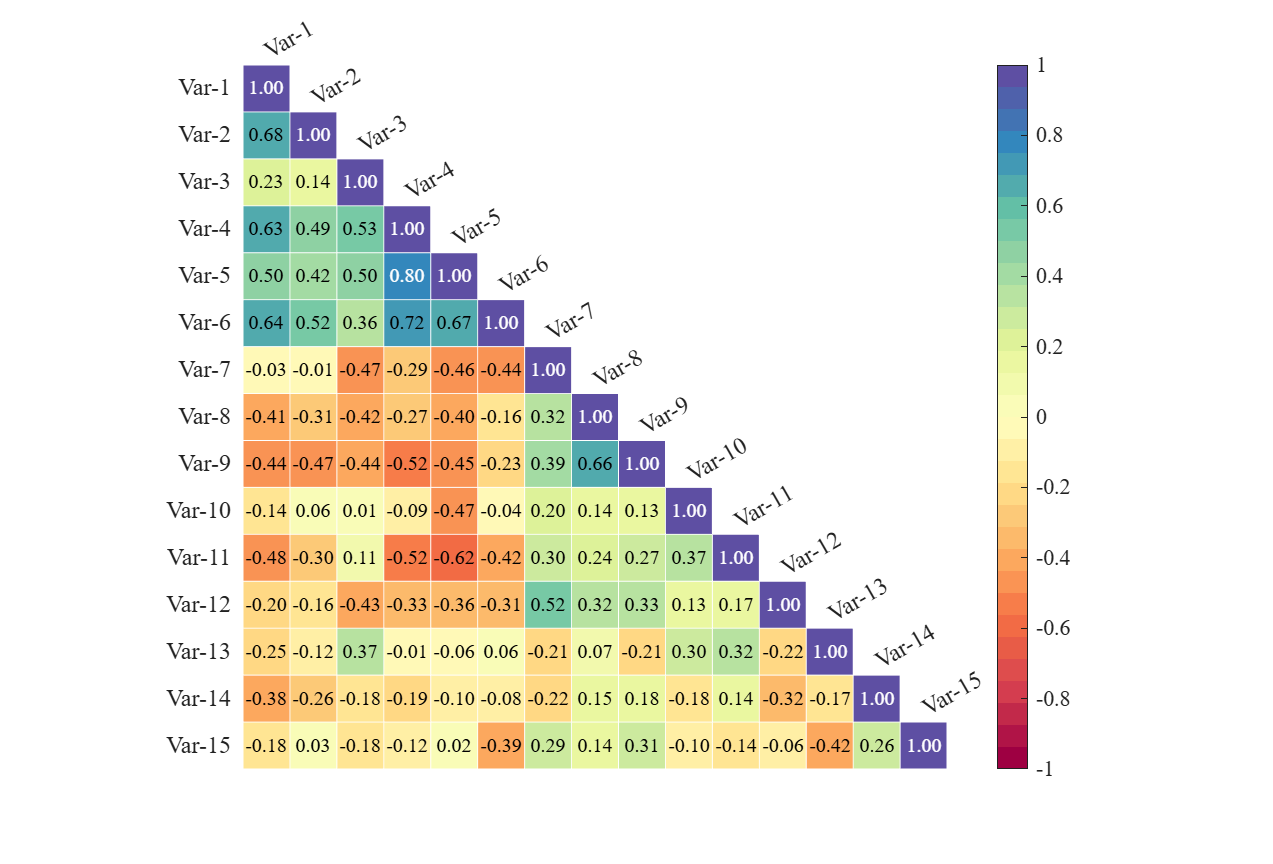

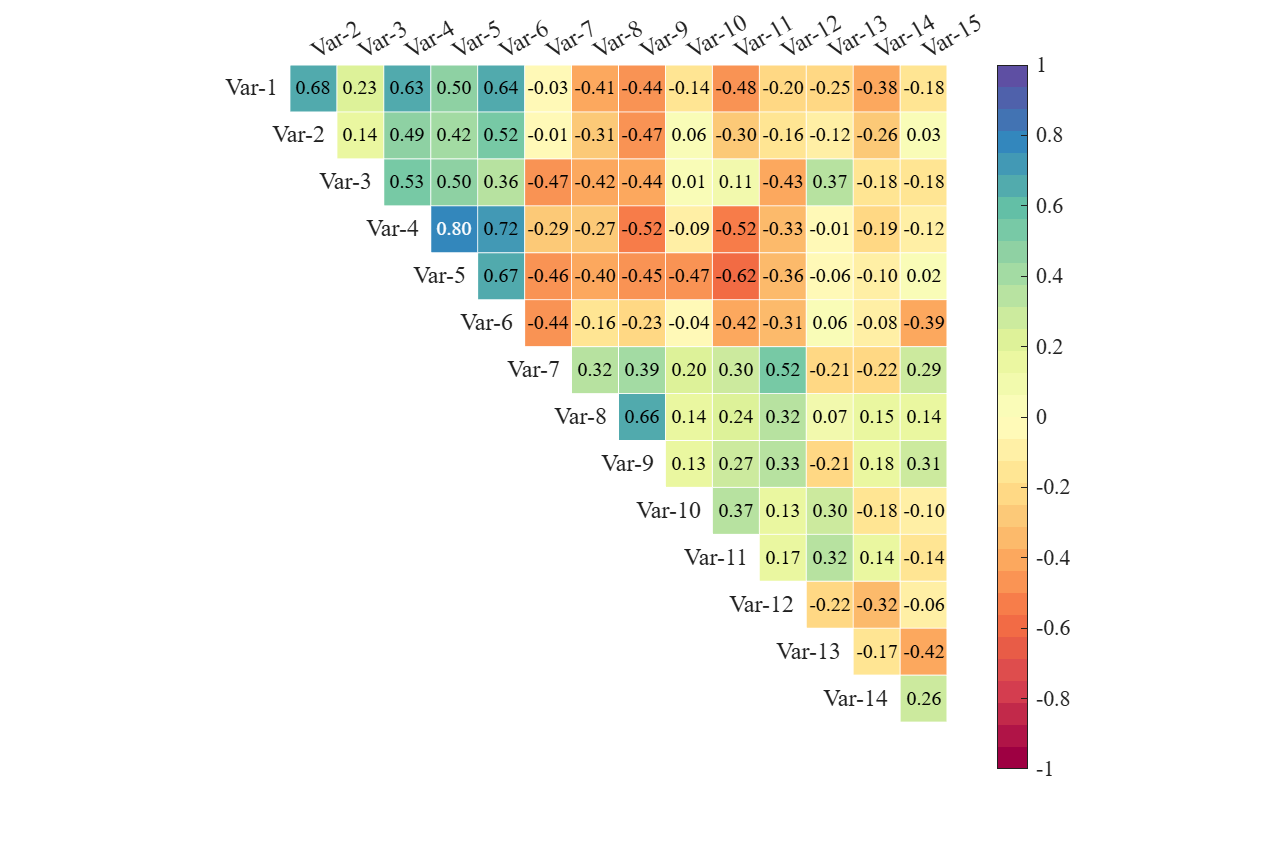

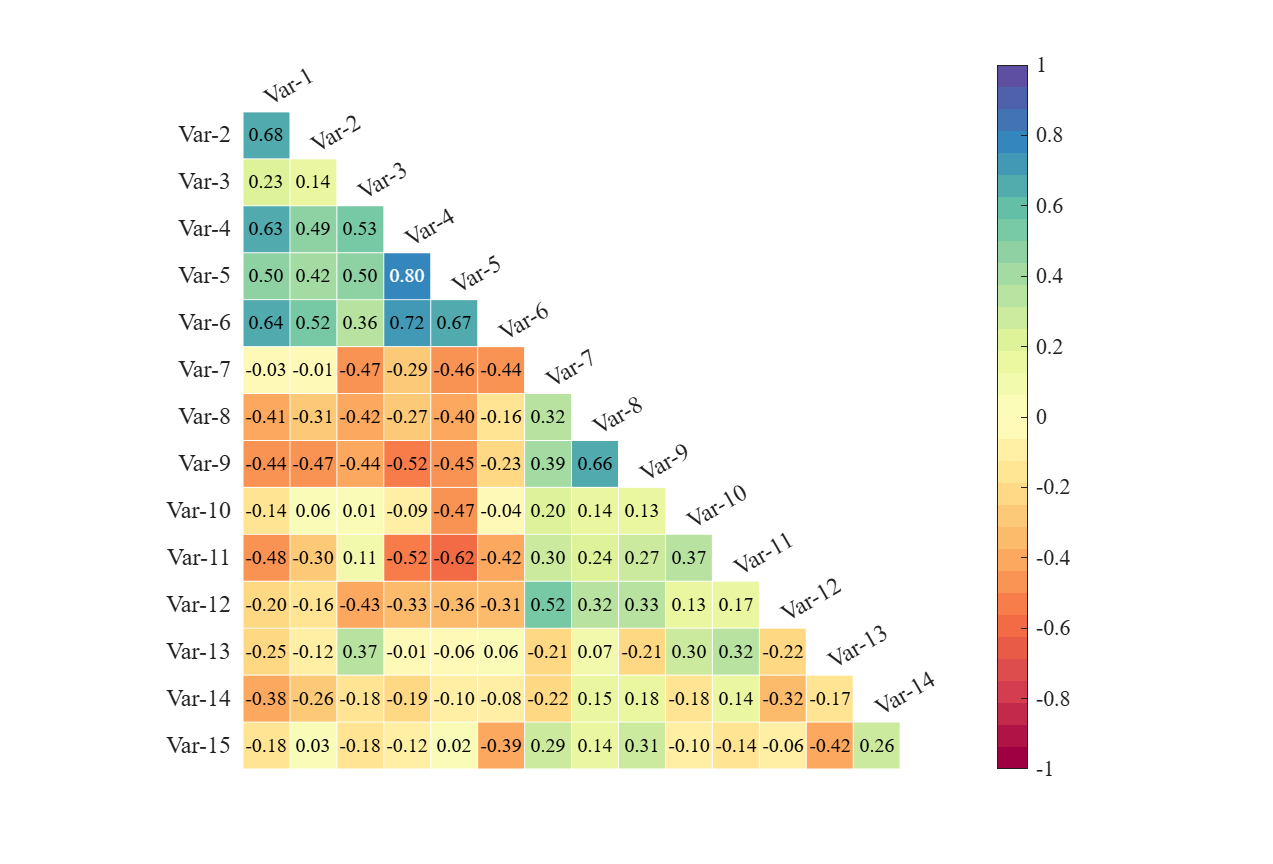

% Made up some data casually (随便捏造了点数据)
X = randn(20, 15) + [(linspace(-1,2.5,20)').*ones(1, 6), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 4)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X);

% + 'triu'   : upper triangle                  : 上三角部分
% + 'tril'   : lower triangle                  : 下三角部分
% + 'triu0'  : upper triangle without diagonal : 扣除对角线上三角部分
% + 'tril0'  : lower triangle without diagonal : 扣除对角线下三角部分

Type = {'triu','tril','triu0','tril0'};
for i = 1:length(Type)
    figure()
    SHM_s1 = SHeatmap(Data, 'Format','sq');
    SHM_s1.draw();
    SHM_s1.setText();
    % set Type (设置格式)
    SHM_s1.setType(Type{i});
end

### `6.2 Set variable labels' String (设置标签名称)`

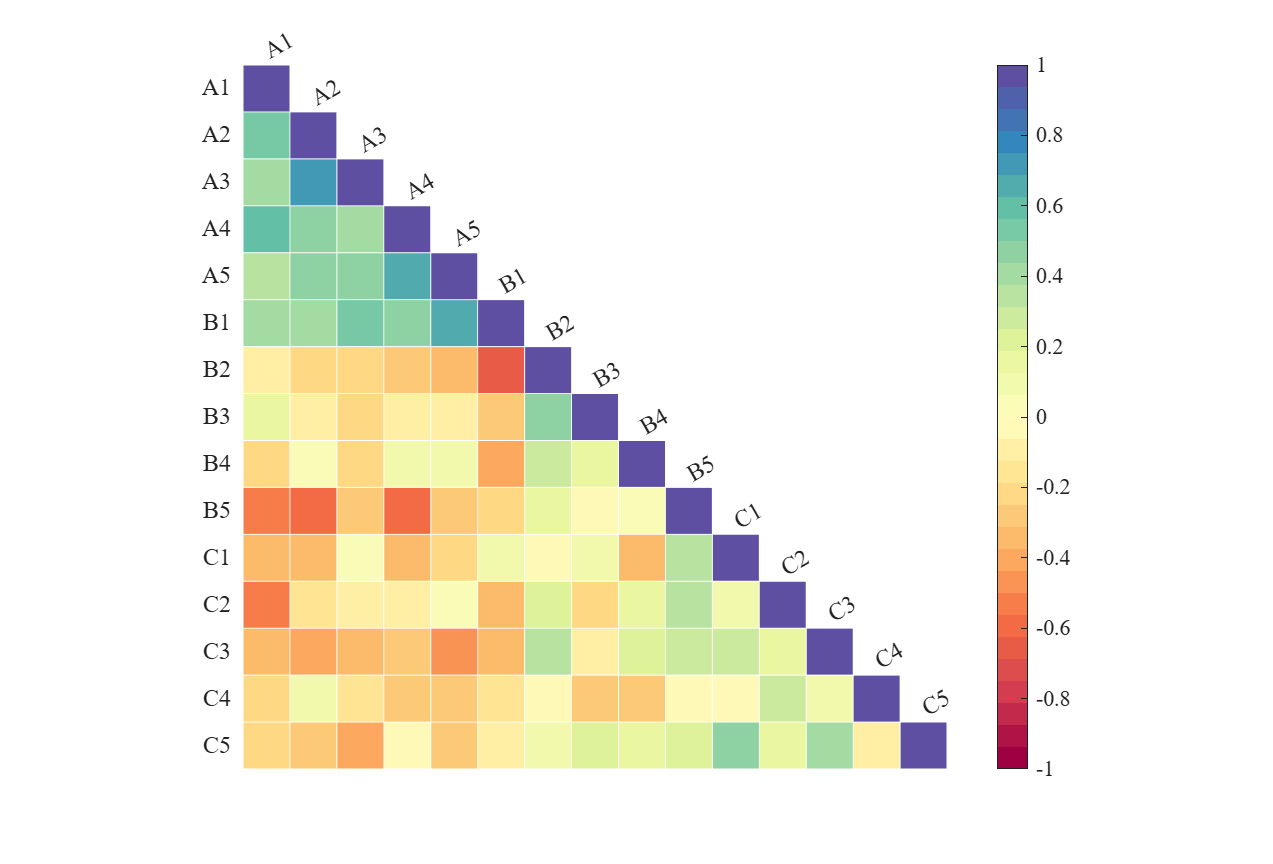

% Made up some data casually (随便捏造了点数据)
X = randn(20, 15) + [(linspace(-1,2.5,20)').*ones(1, 6), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 4)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X);

figure()
SHM_s2 = SHeatmap(Data, 'Format','sq');
SHM_s2.draw();
SHM_s2.setType('tril');

varName = {'A1','A2','A3','A4','A5','B1','B2','B3','B4','B5','C1','C2','C3','C4','C5'};
SHM_s2.setVarName(varName)

### `6.3 Adjust the axis Limit to avoid occlusion (调整轴范围以避免遮挡)`

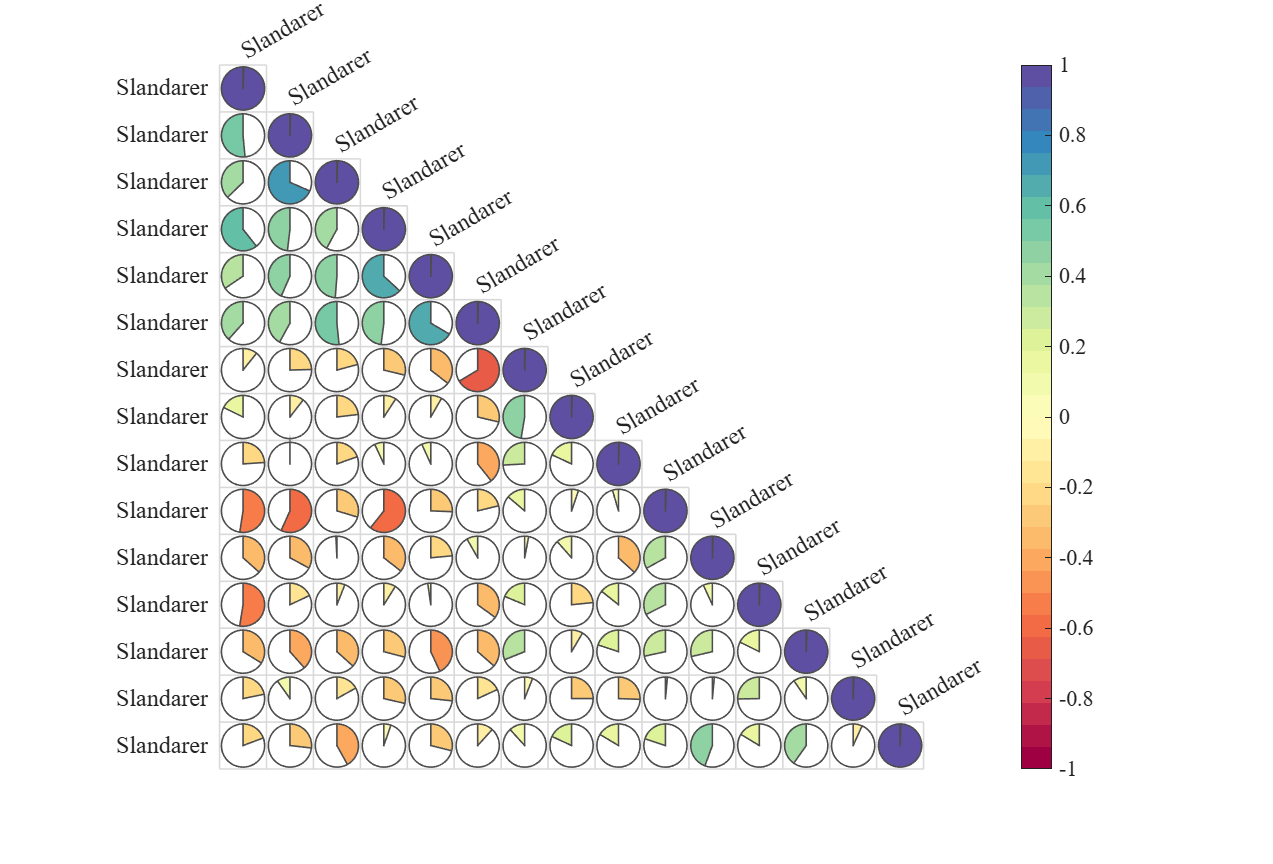

figure()
SHM_s3 = SHeatmap(Data, 'Format','pie');
SHM_s3.draw();
SHM_s3.setType('tril');
SHM_s3.setVarName({'Slandarer'})
ax = gca;
ax.XLim(2) = ax.XLim(2) + 1;

### `6.4 Show upper triangle of all formats (展示所有样式的上三角化)`

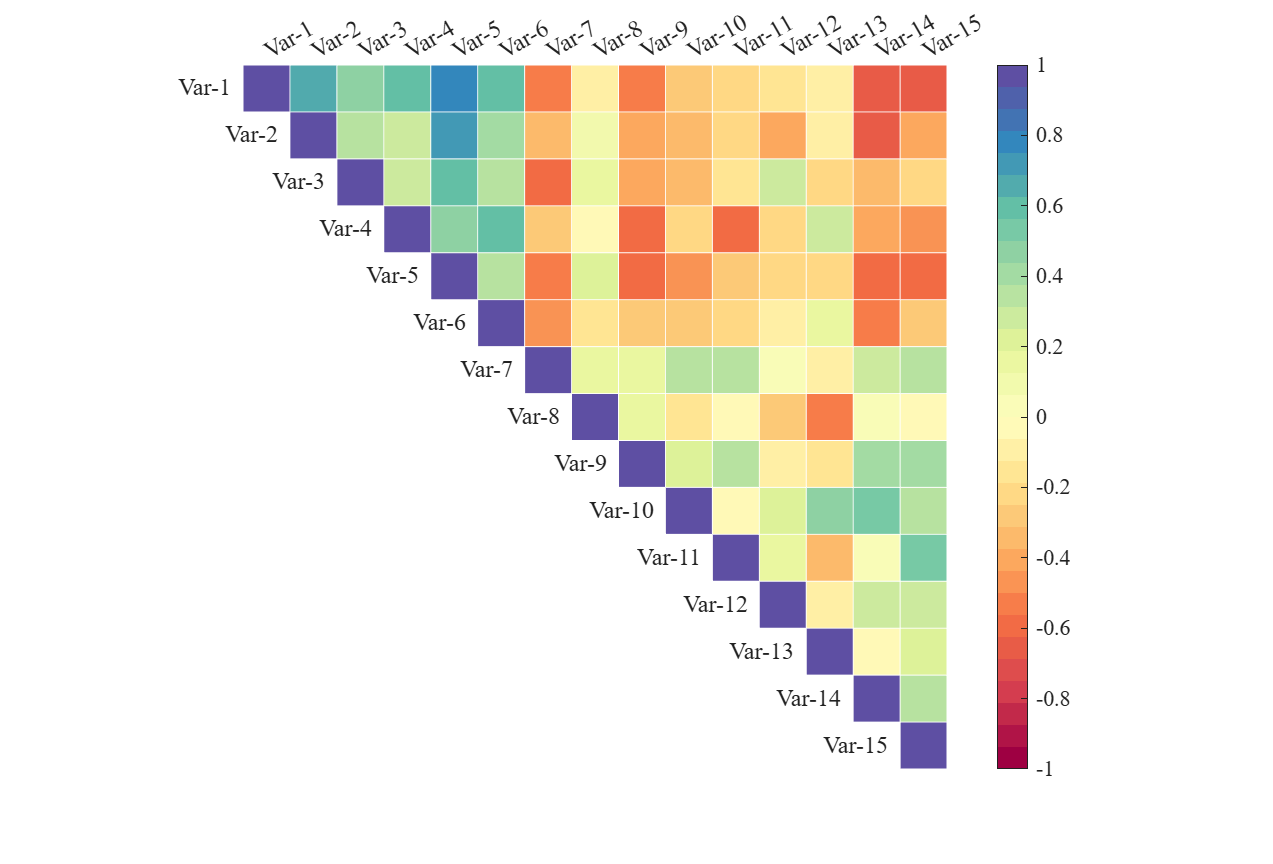

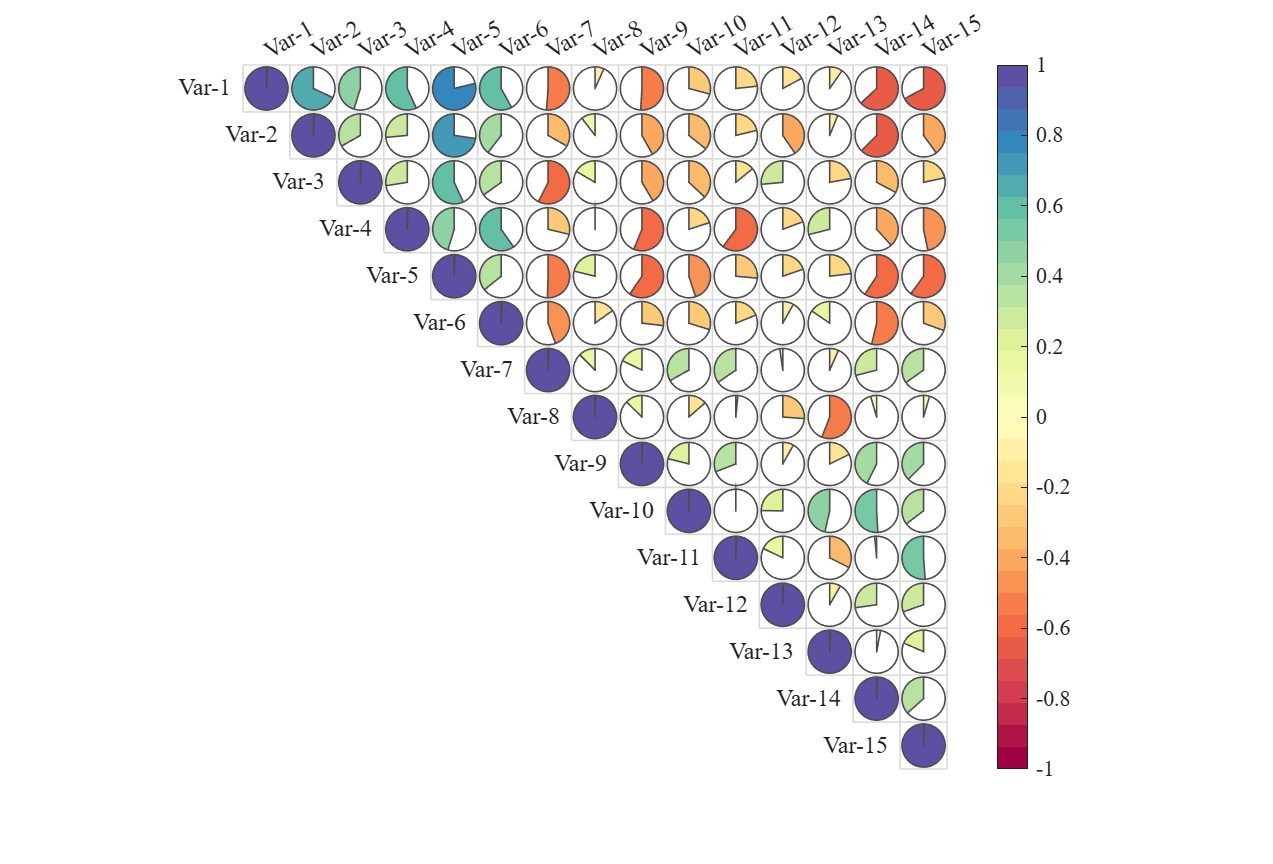

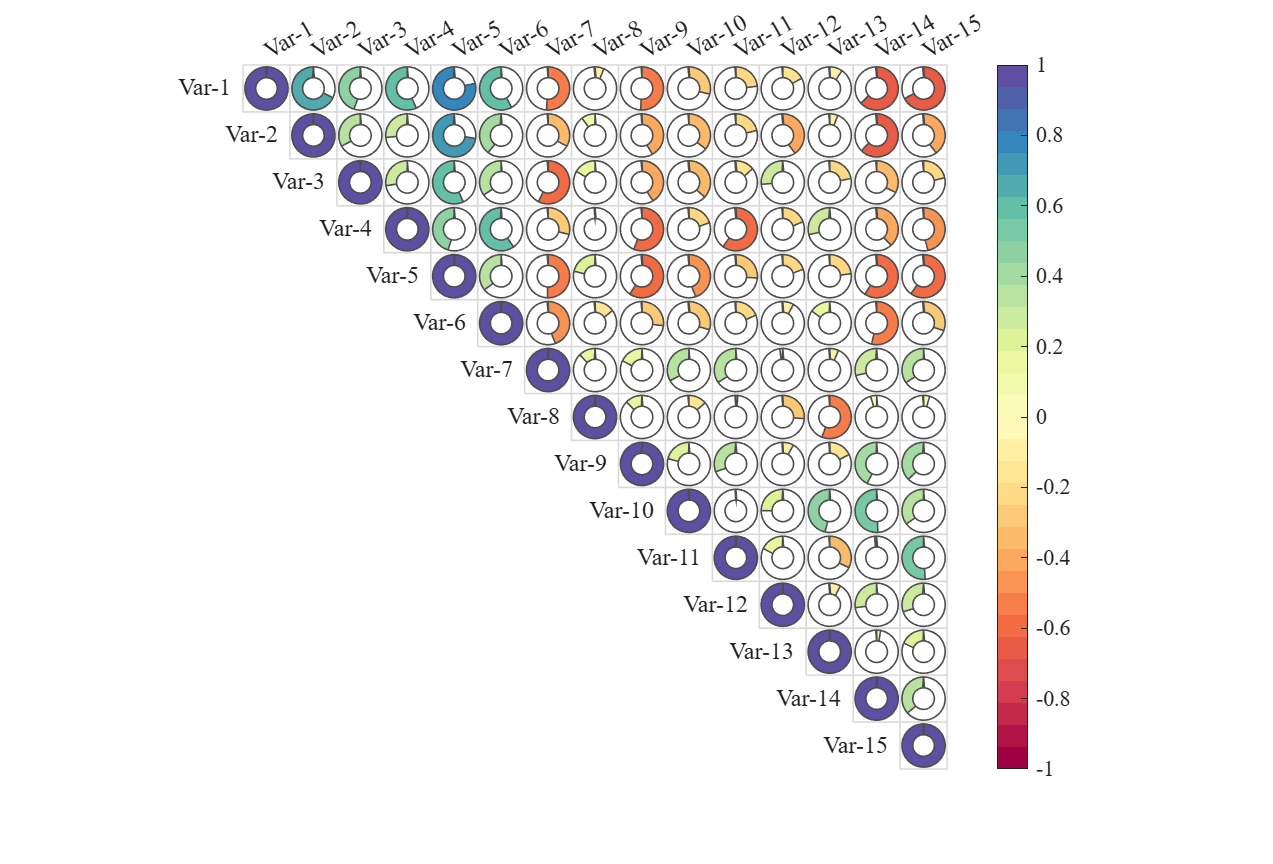

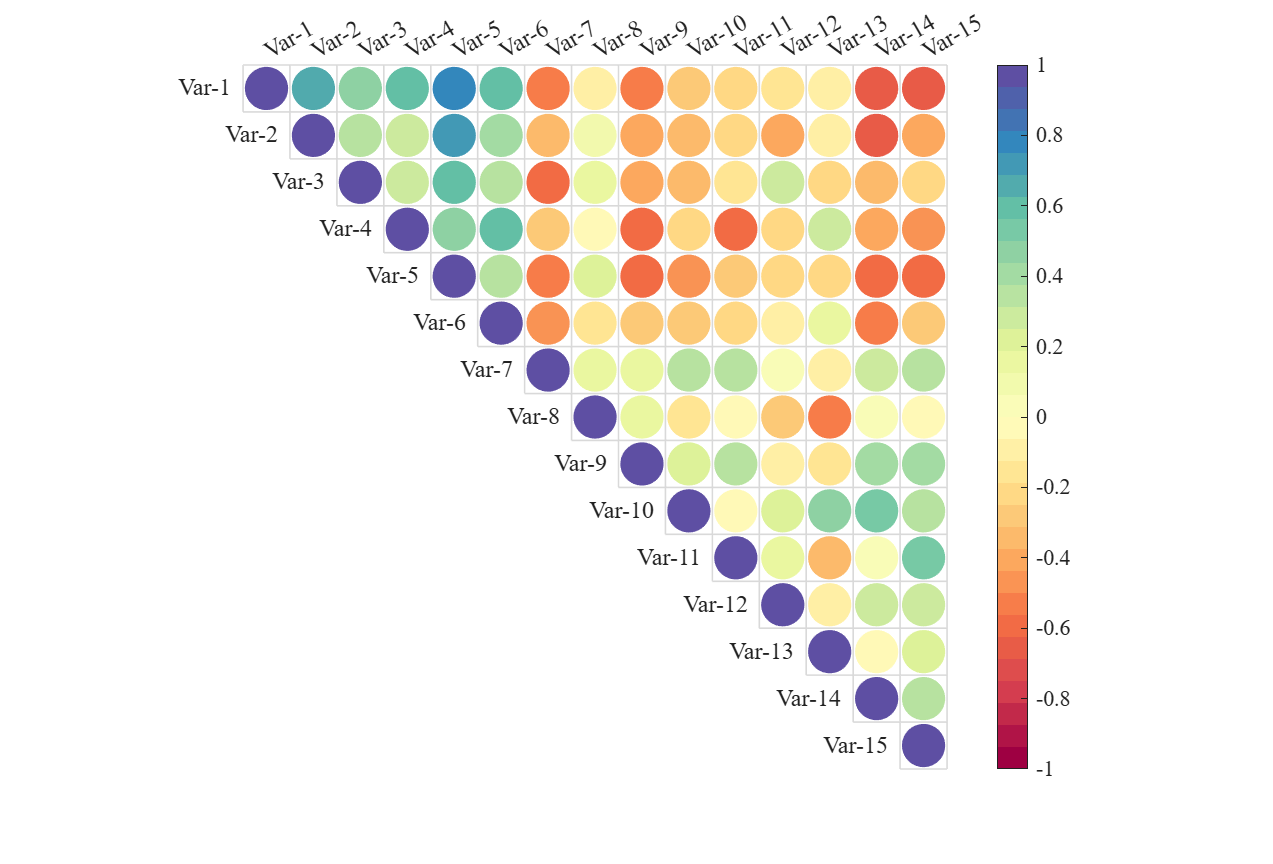

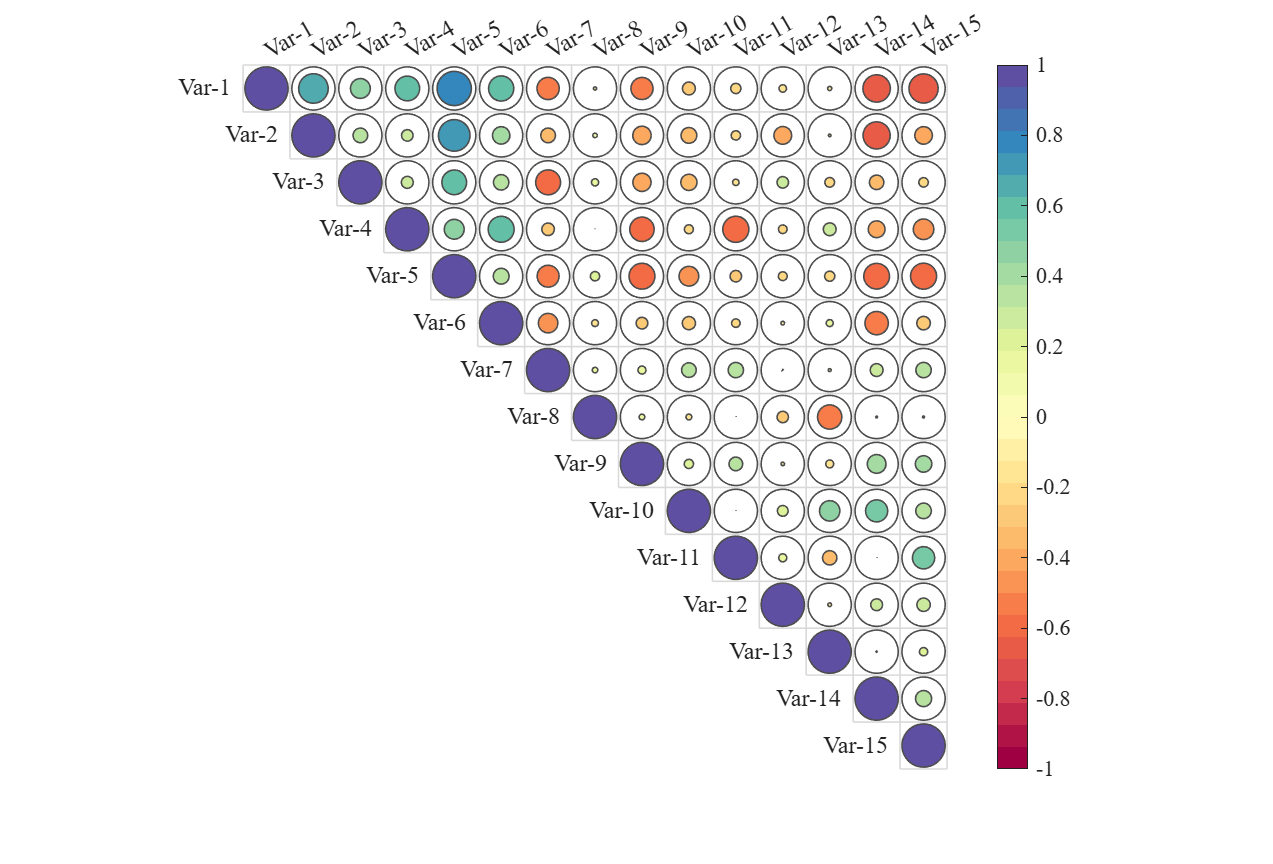

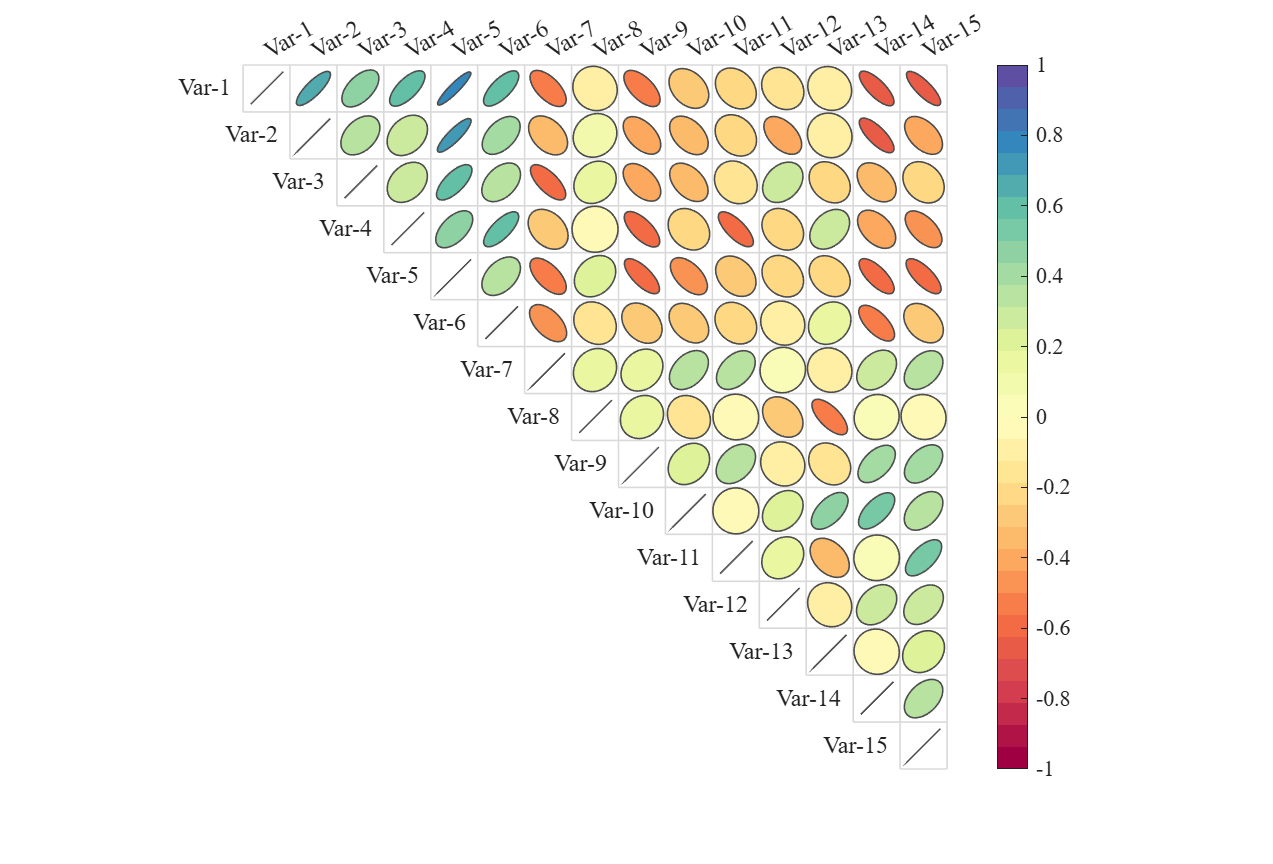

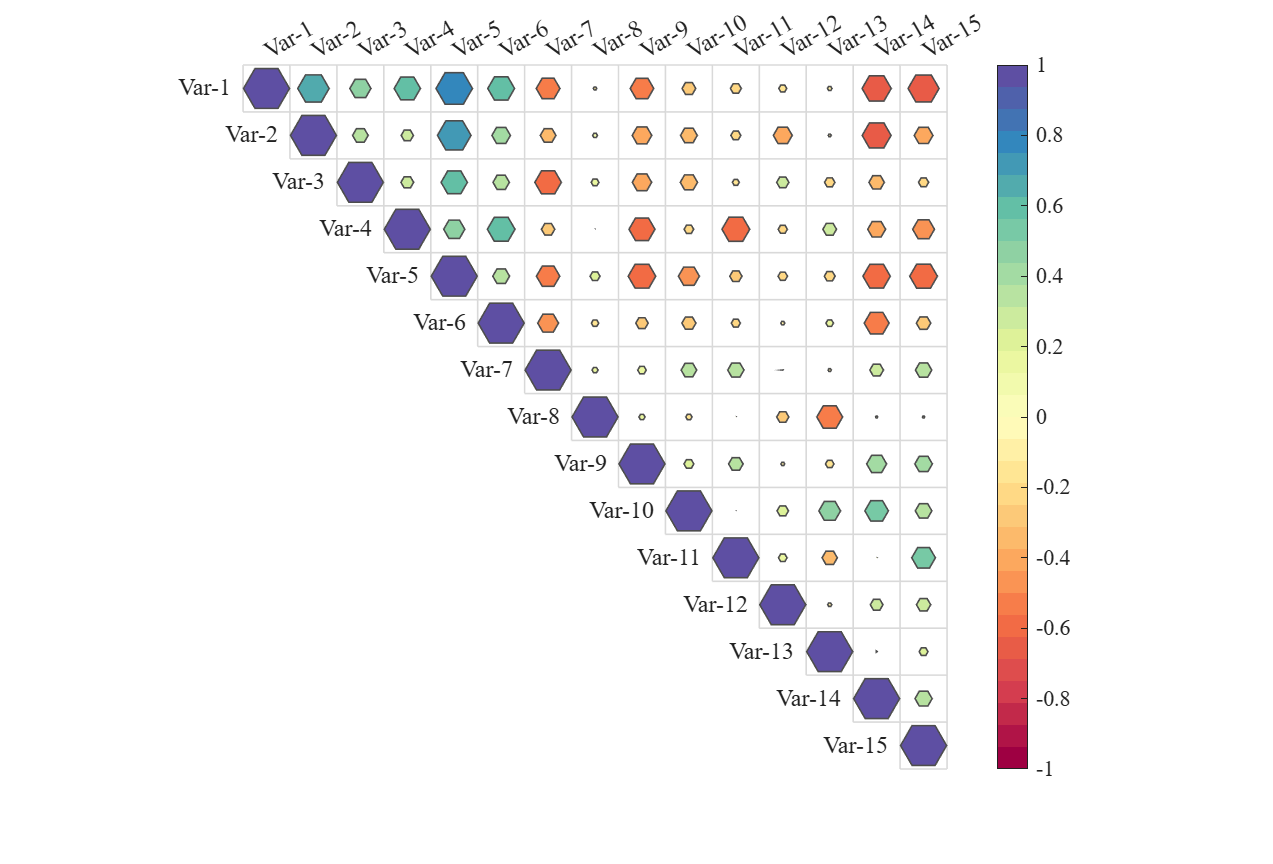

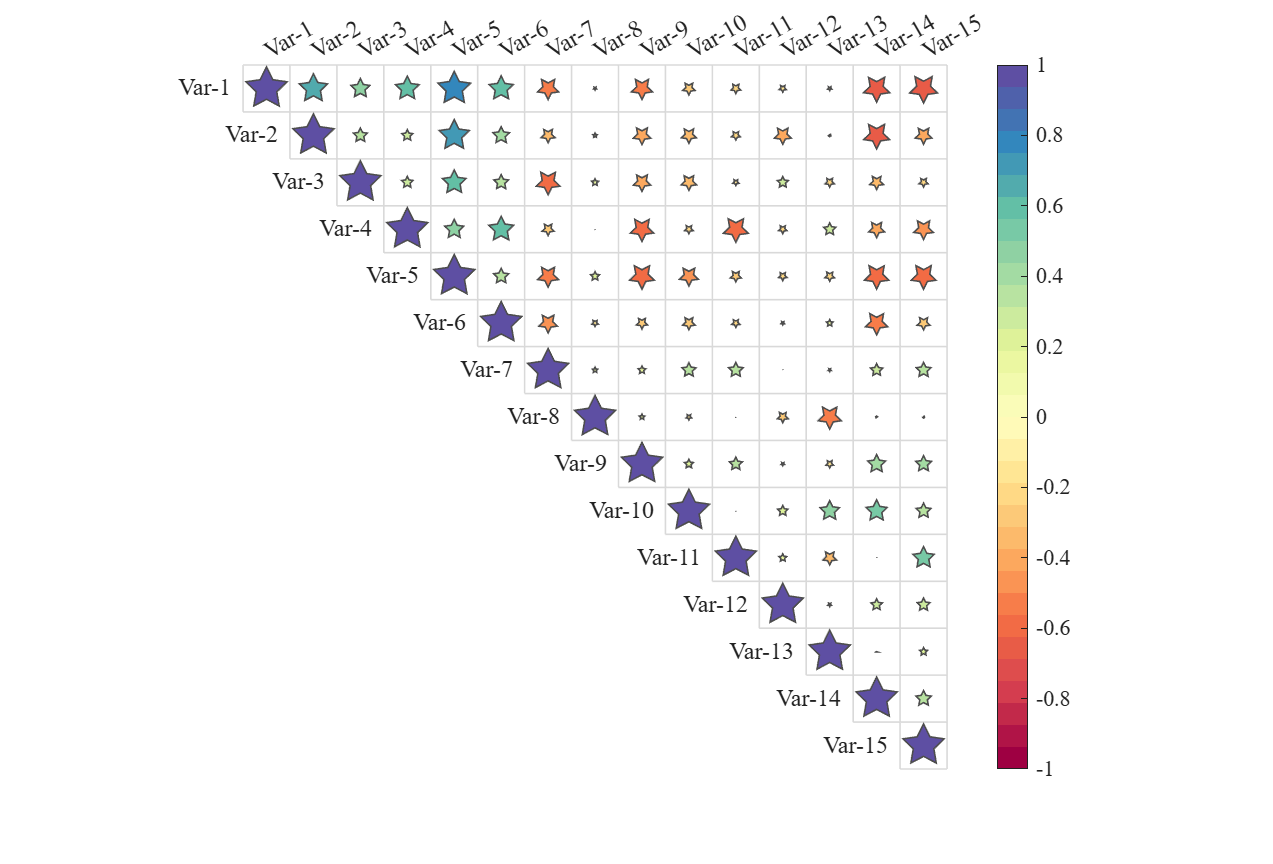

% Made up some data casually (随便捏造了点数据)
X = randn(20, 15) + [(linspace(-1,2.5,20)').*ones(1, 6), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 4)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X);

Format = {'sq','pie','donut','circ','bcirc','oval','hex','star','tril','triu','trilr','triul','asq','acirc'};
for i = 1:length(Format)
    figure()
    SHeatmap(Data, 'Format',Format{i}).draw().setType('triu');
end

### `6.5 Set Label Font (设置标签字体)`

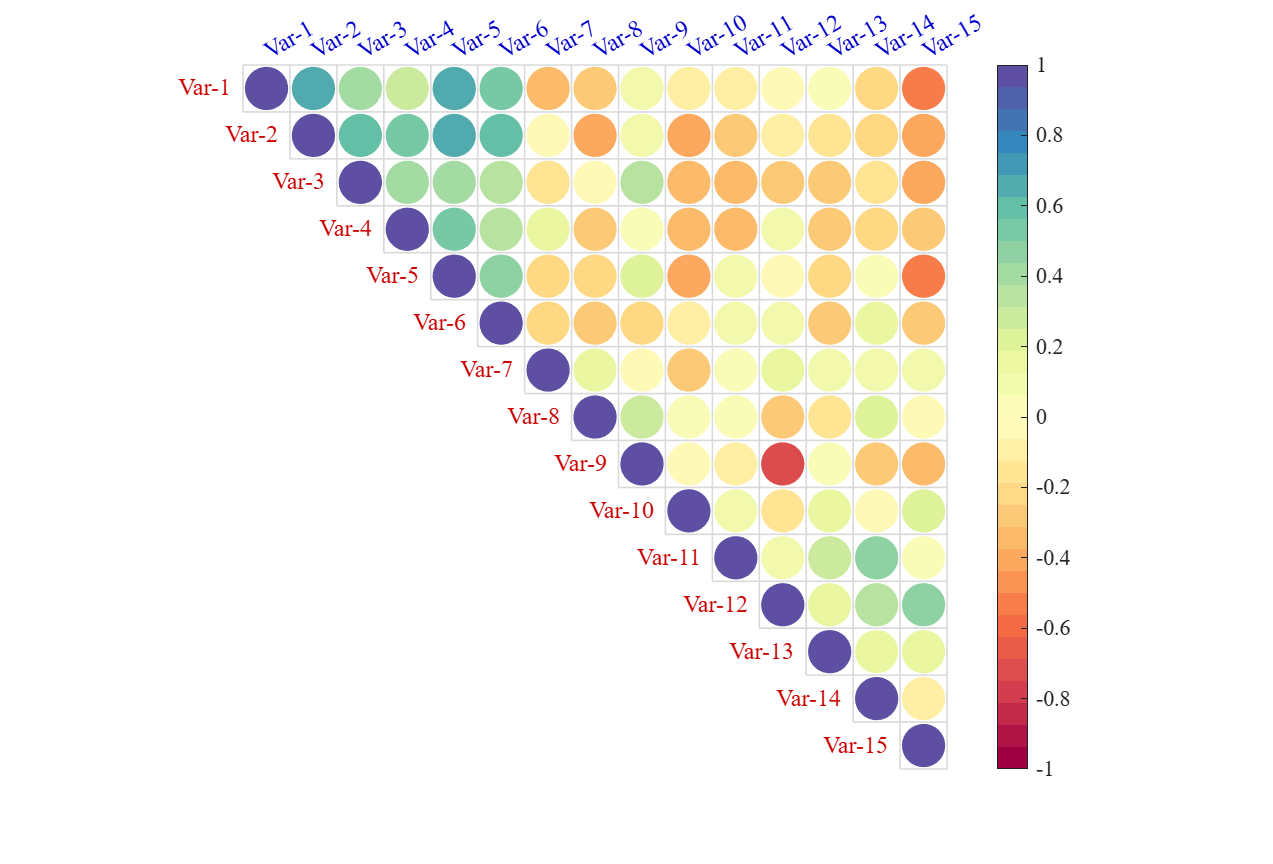

% Made up some data casually (随便捏造了点数据)
X = randn(20, 15) + [(linspace(-1,2.5,20)').*ones(1, 6), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 4)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X);

figure()
SHM_s5 = SHeatmap(Data, 'Format','circ');
SHM_s5.draw();
SHM_s5.setType('triu');
% Set Font Color (设置标签颜色)
SHM_s5.setRowLabel('Color',[.8,0,0])
SHM_s5.setColLabel('Color',[0,0,.8]) 

## `7 Merge two triangle heatmaps (合并两个三角热图)`

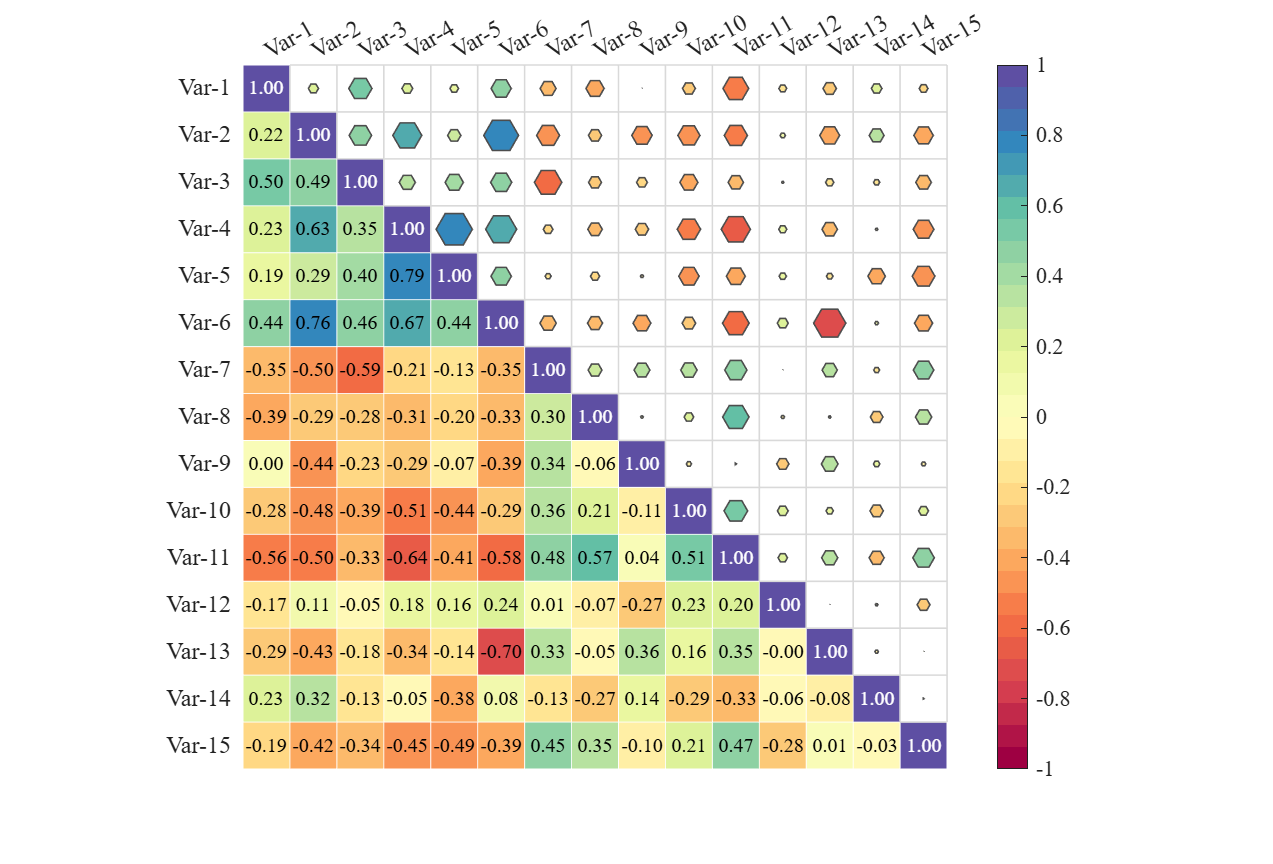

% Made up some data casually (随便捏造了点数据)
X = randn(20,15) + [(linspace(-1,2.5,20)').*ones(1, 6), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 4)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X);

figure()
SHM_m1 = SHeatmap(Data, 'Format','sq').draw().setType('tril');
SHM_m1.setColLabel('Visible','off').setText()

SHM_m2 = SHeatmap(Data, 'Format','hex').draw().setType('triu0');
SHM_m2.setRowLabel('Visible','off').setColLabel('Visible','on') % Show the hidden Var-1 label (显示隐藏的 Var-1 标签)

### `7.2 Merge two triangle heatmaps with two colormaps (合并两个三角热图且使用不同 colormap)`

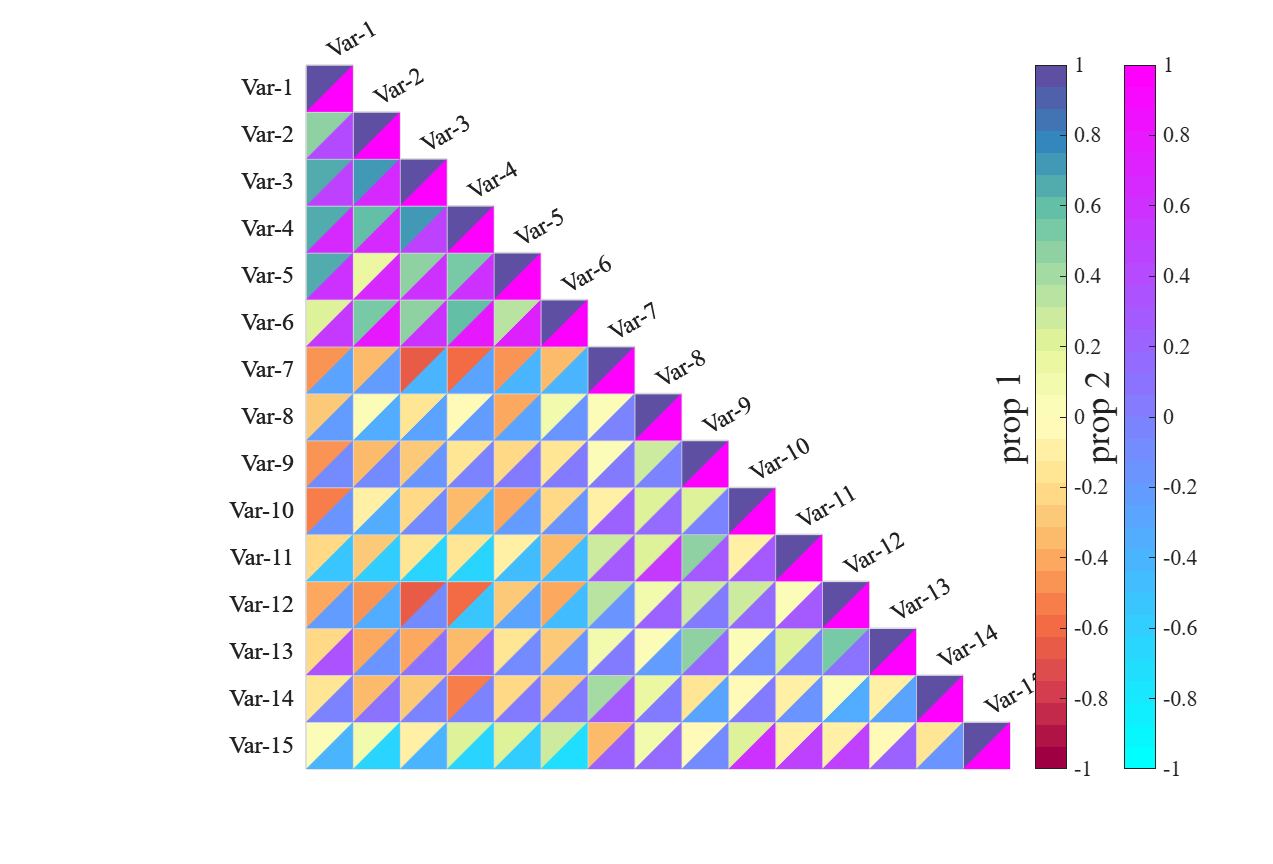

% Made up some data casually (随便捏造了点数据)
X1 = randn(20,15) + [(linspace(-1,2.5,20)').*ones(1, 6), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 4)];
X2 = randn(20,15) + [(linspace(-1,2.5,20)').*ones(1, 6), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 4)];
% Get the correlation matrix (求相关系数矩阵)
Data1 = corr(X1);
Data2 = corr(X2);

figure()
% Draw the first heatmap and freeze colors (绘制第一个热图并冻结配色)
SHM_m1 = SHeatmap(Data1, 'Format','triul').draw().setType('tril');
SHM_m1.freezeColors() 

SHM_m2 = SHeatmap(Data2, 'Format','trilr').draw().setType('tril');
colormap(cool(32));
SHM_m2.Colorbar.Position(1) = SHM_m2.Colorbar.Position(1) + .1;

% Draw label for colorbars (为两个 colorbar 添加标签)
set(SHM_m1.Colorbar.Label, 'String', 'prop 1', 'FontSize', 18, 'Position',[-1.5, 0, 0]);
set(SHM_m2.Colorbar.Label, 'String', 'prop 2', 'FontSize', 18, 'Position',[-1.5, 0, 0]);

## `8 Heatmap with dendrogram (带树状图热图) `

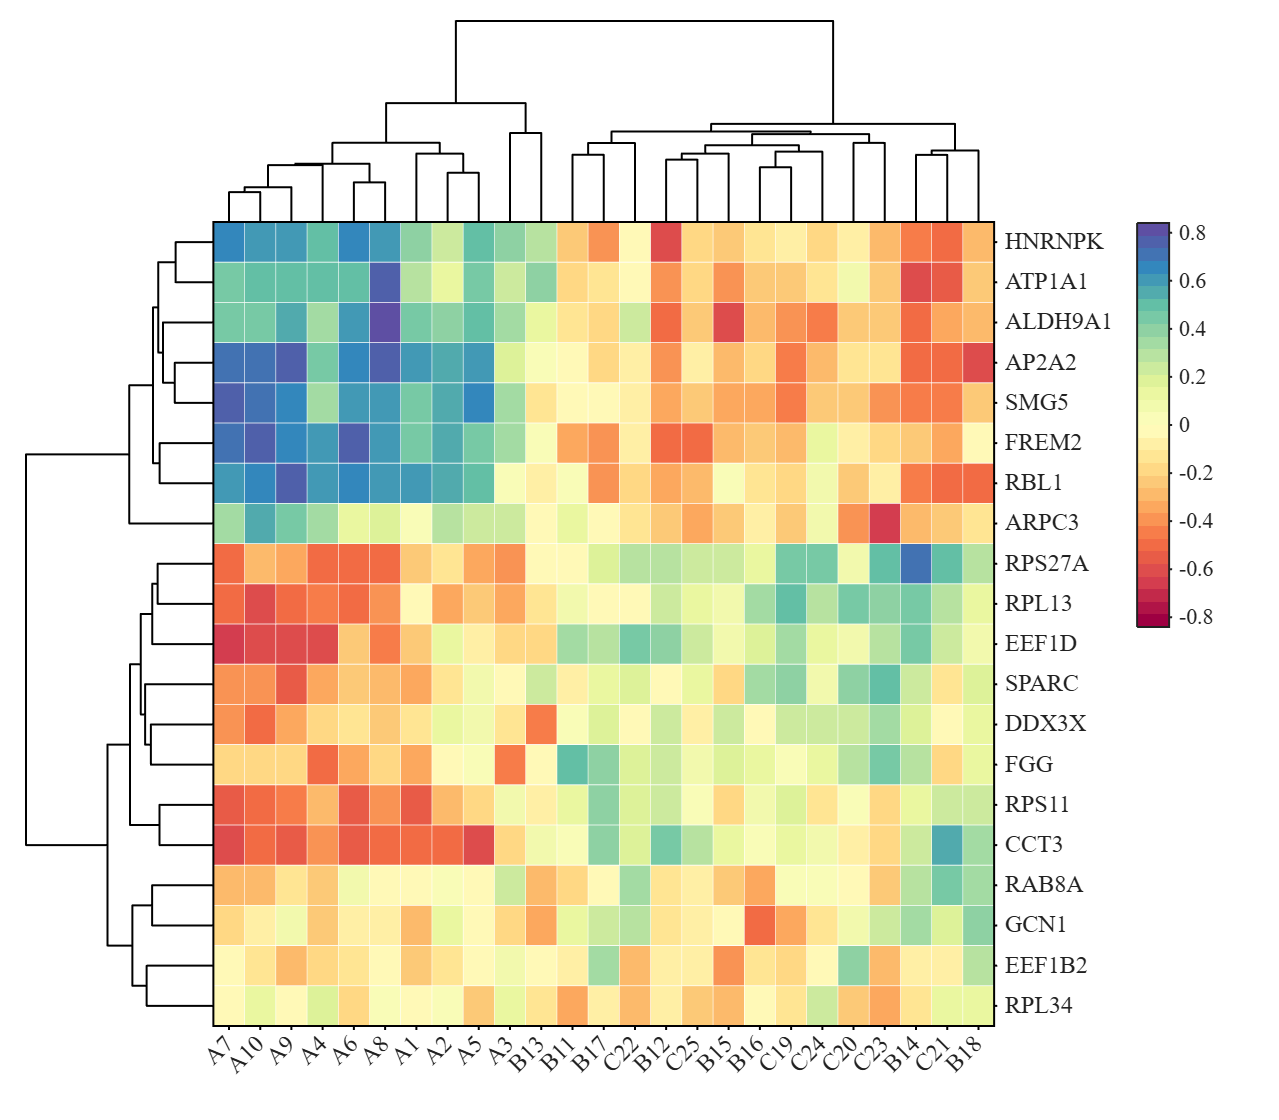

rng(1)
% Made up some data casually (随便捏造了点数据)
X1 = randn(20, 20) + [(linspace(-1,2.5,20)').*ones(1,  8), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 7)];
X2 = randn(20, 25) + [(linspace(-1,2.5,20)').*ones(1, 10), (linspace(.5,-.7,20)').*ones(1, 8), (linspace(.9,-.2,20)').*ones(1, 7)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X1, X2);
% rowName and colName
rowName = {'FREM2','ALDH9A1','RBL1','AP2A2','HNRNPK','ATP1A1','ARPC3','SMG5','RPS27A',...
    'RAB8A','SPARC','DDX3X','EEF1D','EEF1B2','RPS11','RPL13','RPL34','GCN1','FGG','CCT3'};
colName = {'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10','B11','B12','B13',...
    'B14','B15','B16','B17','B18','C19','C20','C21','C22','C23','C24','C25'};

fig = figure('Units','normalized', 'Position',[.1,.05,.5,.7]);
ax = axes('Parent',fig, 'Position',[.02,.08,.76,.9]);

orderL = SDendrogram(Data, 'Orientation','left', 'Parent',ax, 'BasePos',.5, 'Height',6);  % Draw the left dendrogram (绘制左侧树状图)
orderT = SDendrogram(Data, 'Orientation','top' , 'Parent',ax, 'BasePos',.5, 'Height',5);  % Draw the top  dendrogram (绘制顶部树状图)
% Exchange data order (交换数据顺序)
Data = Data(orderL, orderT);
% Draw heatmap (绘制热图)
SHM_t1 = SHeatmap(Data, 'Format','sq', 'Parent',ax).draw();
SHM_t1.setRowLabelLocation('right').setColName(colName(orderT))
SHM_t1.setColLabelLocation('bottom').setRowName(rowName(orderL))
SHM_t1.setColLabel('Rotation',45).setFrame()
% Draw colorbar (绘制颜色条)
axis(ax, 'tight')
ax.DataAspectRatioMode = 'auto';
yn = size(Data, 1); yh = .9.*yn./(yn + 5) + .08;
SHM_t1.Colorbar.Position = [.89, yh - .36, .025, .36];

## `9 Grouping block (分组方块)`

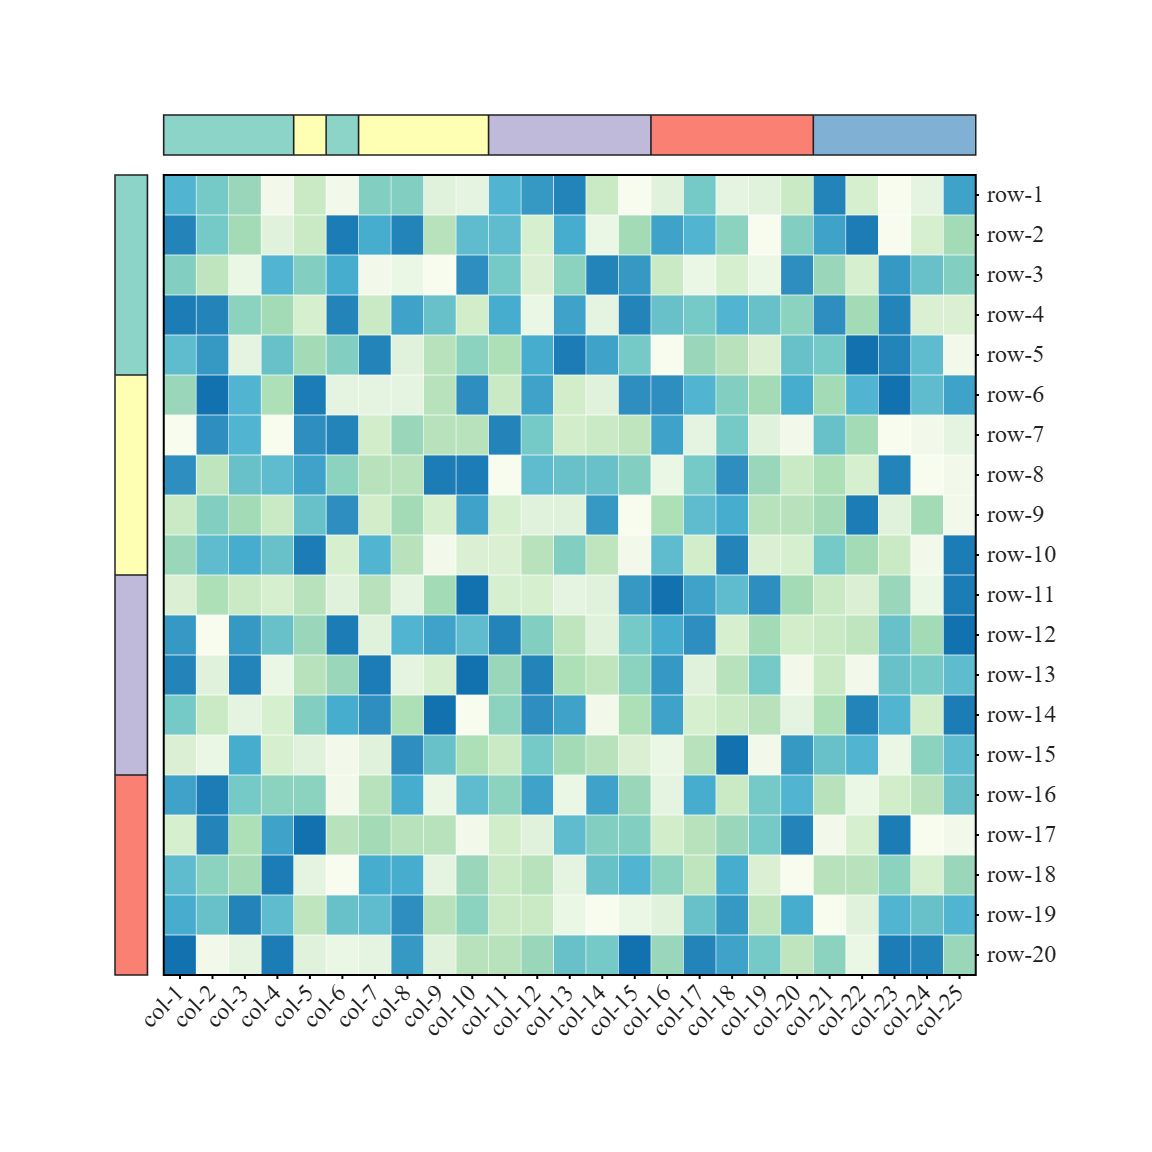

% Made up some data casually (随便捏造了点数据)
rowGroup = [1,1,1,1,1,2,2,2,2,2,3,3,3,3,3,4,4,4,4,4];
colGroup = [1,1,1,1,2,1,2,2,2,2,3,3,3,3,3,4,4,4,4,4,5,5,5,5,5];
rowName = compose('row-%d', 1:20);
colName = compose('col-%d', 1:25);
Data = rand(20, 25);

% create figure (图窗创建)
fig = figure('Units','normalized', 'Position',[.1,.05,.45,.72]);
ax = axes('Parent',fig, 'Position',[.1,.15,.75,.75]);

SClusterBlock(rowGroup, 'Orientation','left', 'Parent',ax); % Draw the left Block (绘制左侧分组方块)
SClusterBlock(colGroup, 'Orientation','top' , 'Parent',ax); % Draw the top  Block (绘制顶部分组方块)
% Draw heatmap (绘制热图)
SHM_b1 = SHeatmap(Data, 'Format','sq', 'Parent',ax).draw();
SHM_b1.setRowLabelLocation('right').setColName(colName)
SHM_b1.setColLabelLocation('bottom').setRowName(rowName)
SHM_b1.setColLabel('Rotation',45).setFrame()

colorbar(ax, 'off');
clim(ax, [-.2, 1])
axis(ax, 'tight')
ax.DataAspectRatioMode = 'auto';

## `10 Multilayer grouping (多层分组)`

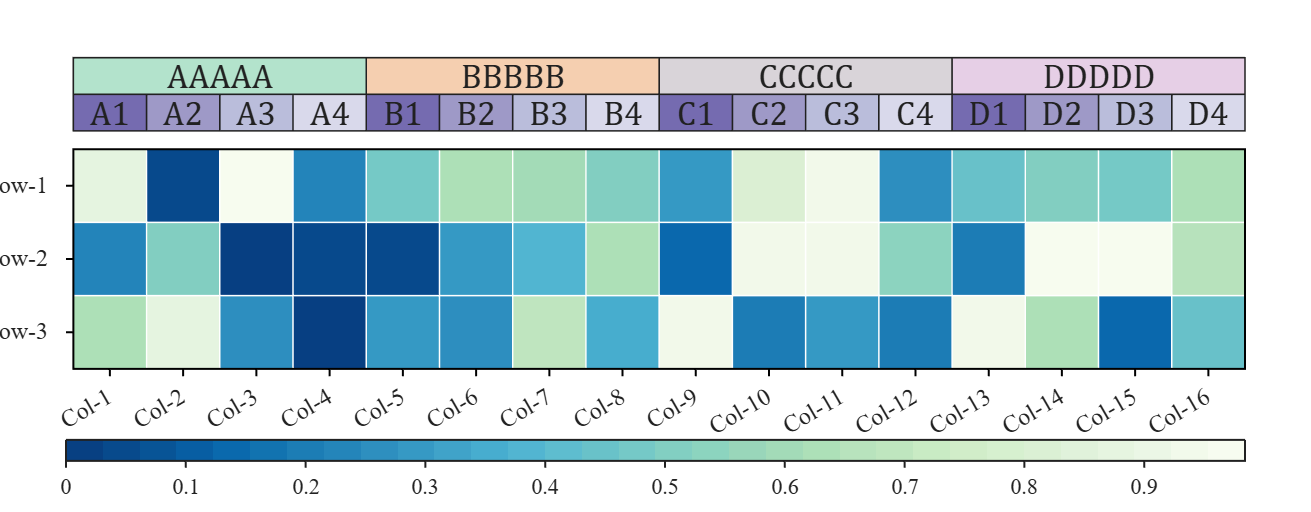

Data = rand(3, 16);
Class1 = [1,1,1,1, 2,2,2,2, 3,3,3,3, 4,4,4,4];
Class2 = [1,2,3,4, 1,2,3,4, 1,2,3,4, 1,2,3,4];
ClassName1 = {'AAAAA','BBBBB','CCCCC','DDDDD'};
ClassName2 = {'A1','A2','A3','A4','B1','B2','B3','B4','C1','C2','C3','C4','D1','D2','D3','D4'};
% Color (配色)
CList1 = [.70,.89,.80; .96,.81,.69; .85,.83,.85; .90,.81,.90];
CList2 = [.46,.42,.69; .62,.60,.78; .73,.74,.86; .85,.85,.92];

% create figure and axes (图窗及坐标区域创建)
fig = figure('Units','normalized', 'Position',[.05,.15,.72,.45]);
ax = axes('Parent',fig, 'Position',[.05,.15,.9,.85]);
% Draw Heatmap
SHM_m1 = SHeatmap(Data, 'Format','sq', 'Parent',ax);
SHM_m1.RowName = compose('Row-%d', 1:3);
SHM_m1.ColName = compose('Col-%d', 1:16);
SHM_m1.draw().setFrame();
% Draw Block
[X1, Y1] = SClusterBlock(Class1, 'Orientation','top', 'BasePos',-.25, 'Height',.5, 'ColorList',CList1, 'Parent',ax);
[X2, Y2] = SClusterBlock(Class2, 'Orientation','top', 'BasePos',.25 , 'Height',.5, 'ColorList',CList2, 'Parent',ax);
% text
textProp = {'FontSize',17, 'HorizontalAlignment','center', 'FontName','Cambria'};
for i = 1:length(X1), text(ax, X1(i), Y1(i), ClassName1{i}, textProp{:}); end
for i = 1:length(X2), text(ax, X2(i), Y2(i), ClassName2{i}, textProp{:}); end

SHM_m1.Colorbar.Location = 'southoutside';
SHM_m1.Colorbar.Position = [.05, .1, .9, .04];

## `11 Tree and Group block (树状图及分组方块)`

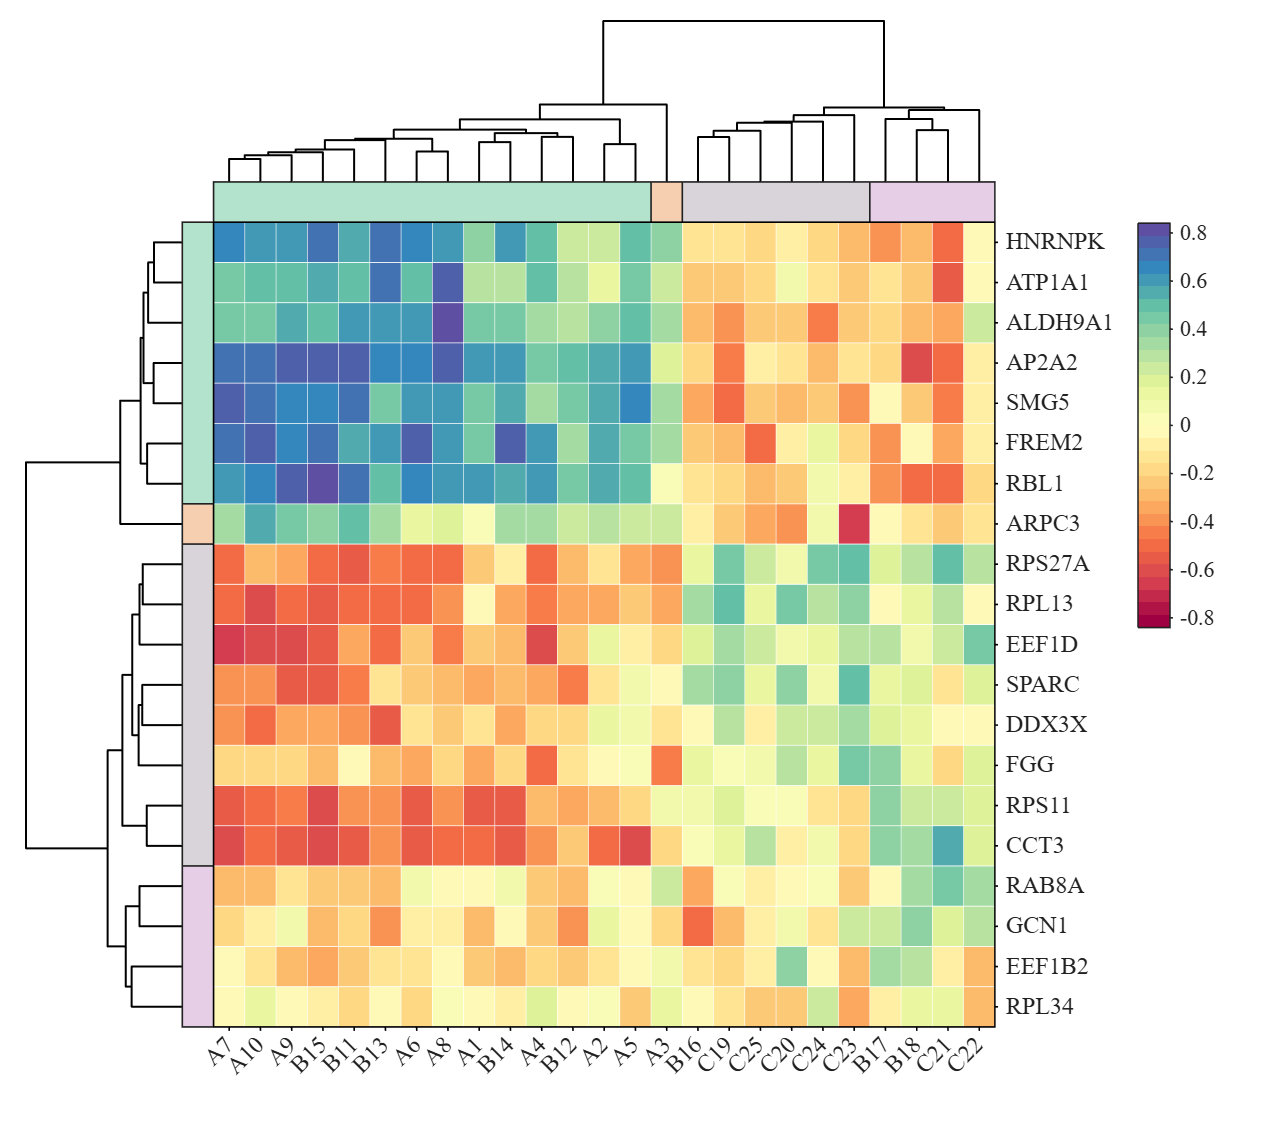

rng(1)
% Made up some data casually (随便捏造了点数据)
X1 = randn(20, 20) + [(linspace(-1,2.5,20)').*ones(1,  8), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 7)];
X2 = randn(20, 25) + [(linspace(-1,2.5,20)').*ones(1, 15), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 5)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X1, X2);
% rowName and colName
rowName = {'FREM2','ALDH9A1','RBL1','AP2A2','HNRNPK','ATP1A1','ARPC3','SMG5','RPS27A',...
           'RAB8A','SPARC','DDX3X','EEF1D','EEF1B2','RPS11','RPL13','RPL34','GCN1','FGG','CCT3'};
colName = {'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10','B11','B12','B13',...
           'B14','B15','B16','B17','B18','C19','C20','C21','C22','C23','C24','C25'};

CList = [.70,.89,.80; .96,.81,.69; .85,.83,.85; .90,.81,.90];

fig = figure('Units','normalized', 'Position',[.1,.05,.5,.7]);
ax = axes('Parent',fig, 'Position',[.02,.08,.76,.9]);
% Draw tree and block (绘制树状图及分组方块)
[orderL, objL] = SDendrogram(Data, 'Orientation','left', 'Parent',ax, 'BasePos',-.5, 'Height',5, 'MaxClust',4);  % Draw the left dendrogram (绘制左侧树状图)
[orderT, objT] = SDendrogram(Data, 'Orientation','top' , 'Parent',ax, 'BasePos',-.5, 'Height',4, 'MaxClust',4);  % Draw the top  dendrogram (绘制顶部树状图)
Data = Data(orderL, orderT);  % Exchange data order (交换数据顺序)
SClusterBlock(objL.Group, 'ColorList',CList ,'Orientation','left', 'Parent',ax, 'BasePos',.5); % Draw the left Block (绘制左侧分组方块)
SClusterBlock(objT.Group, 'ColorList',CList, 'Orientation','top' , 'Parent',ax, 'BasePos',.5); % Draw the top  Block (绘制顶部分组方块)
% Draw heatmap (绘制热图)
SHM = SHeatmap(Data, 'Format','sq', 'Parent',ax).draw();
SHM.setRowLabelLocation('right').setColName(colName(orderT))
SHM.setColLabelLocation('bottom').setRowName(rowName(orderL))
SHM.setColLabel('Rotation',45).setFrame('LineWidth',.8)
% Draw colorbar (绘制颜色条)
axis(ax, 'tight')
ax.DataAspectRatioMode = 'auto';
yn = size(Data, 1); yh = .9.*yn./(yn + 5) + .08;
SHM.Colorbar.Position = [.89, yh - .36, .025, .36];

## `12 Text Format (数值文本格式)`

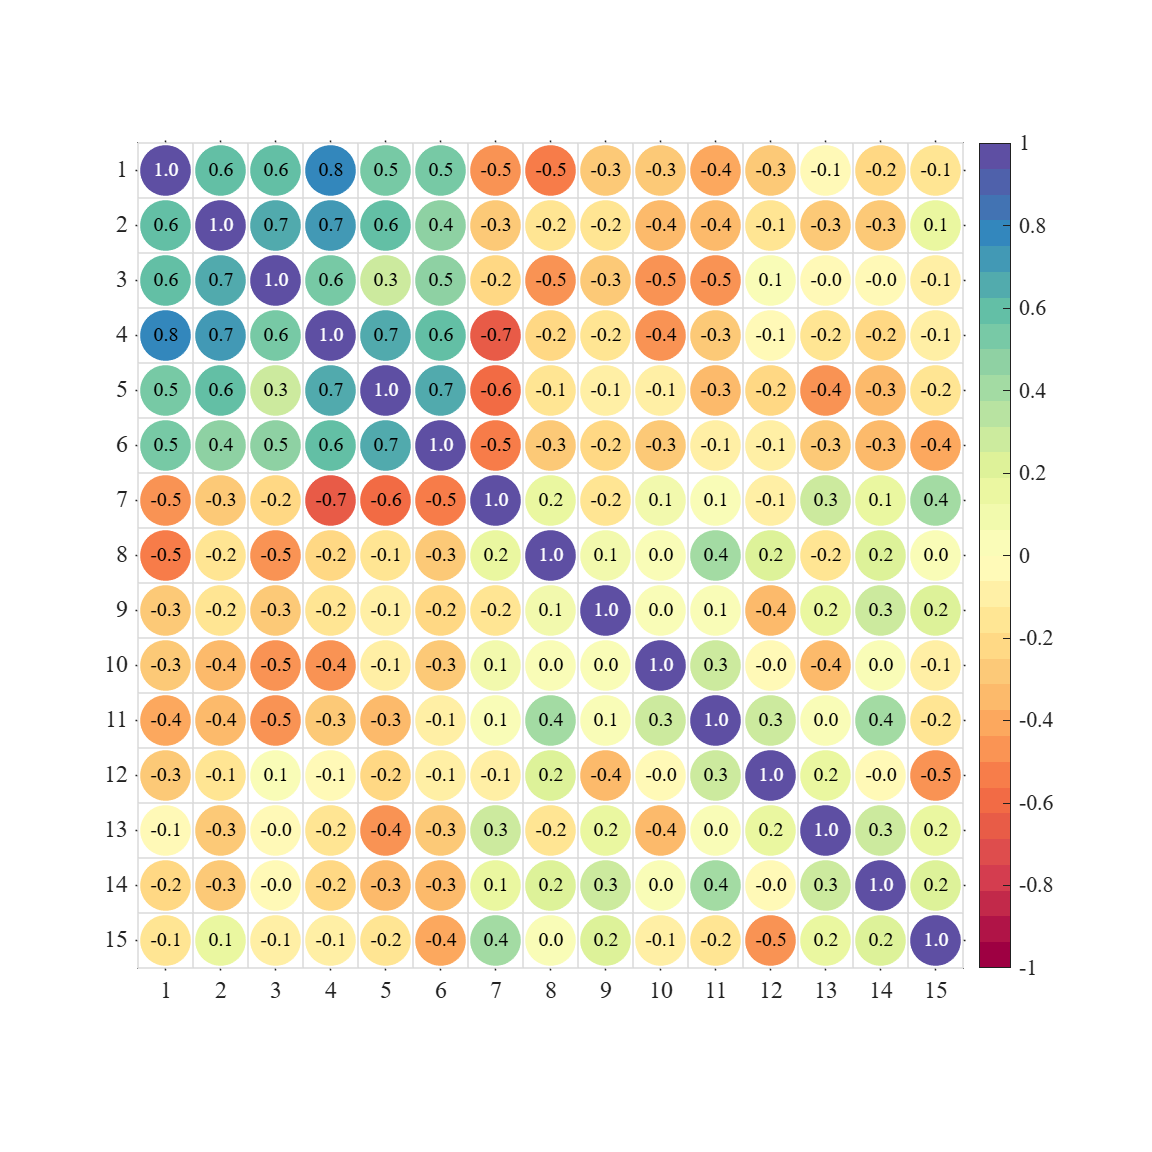

% Made up some data casually (随便捏造了点数据)
X = randn(20, 15) + [(linspace(-1, 2.5, 20)').*ones(1, 6), ...
                     (linspace(.5, -.7, 20)').*ones(1, 5), ...
                     (linspace(.9, -.2, 20)').*ones(1, 4)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X);

% create figure (图窗创建)
figure('Units','normalized', 'Position',[.1,.05,.45,.72])

% Draw heat map with texts (绘制有文本热图)
SHM12 = SHeatmap(Data, 'Format','circ').draw().setText();

% Set text format (调整数值文本格式)
SHM12.setTextFormat(@(x) sprintf('%0.1f', x))

% SHM12.setTextFormat(@(x)sprintf('%0.1fS', x))
% SHM12.setTextFormat(@(x)sprintf('%0.1e', x))

### `12.2 Displaying significance (显示显著性)`

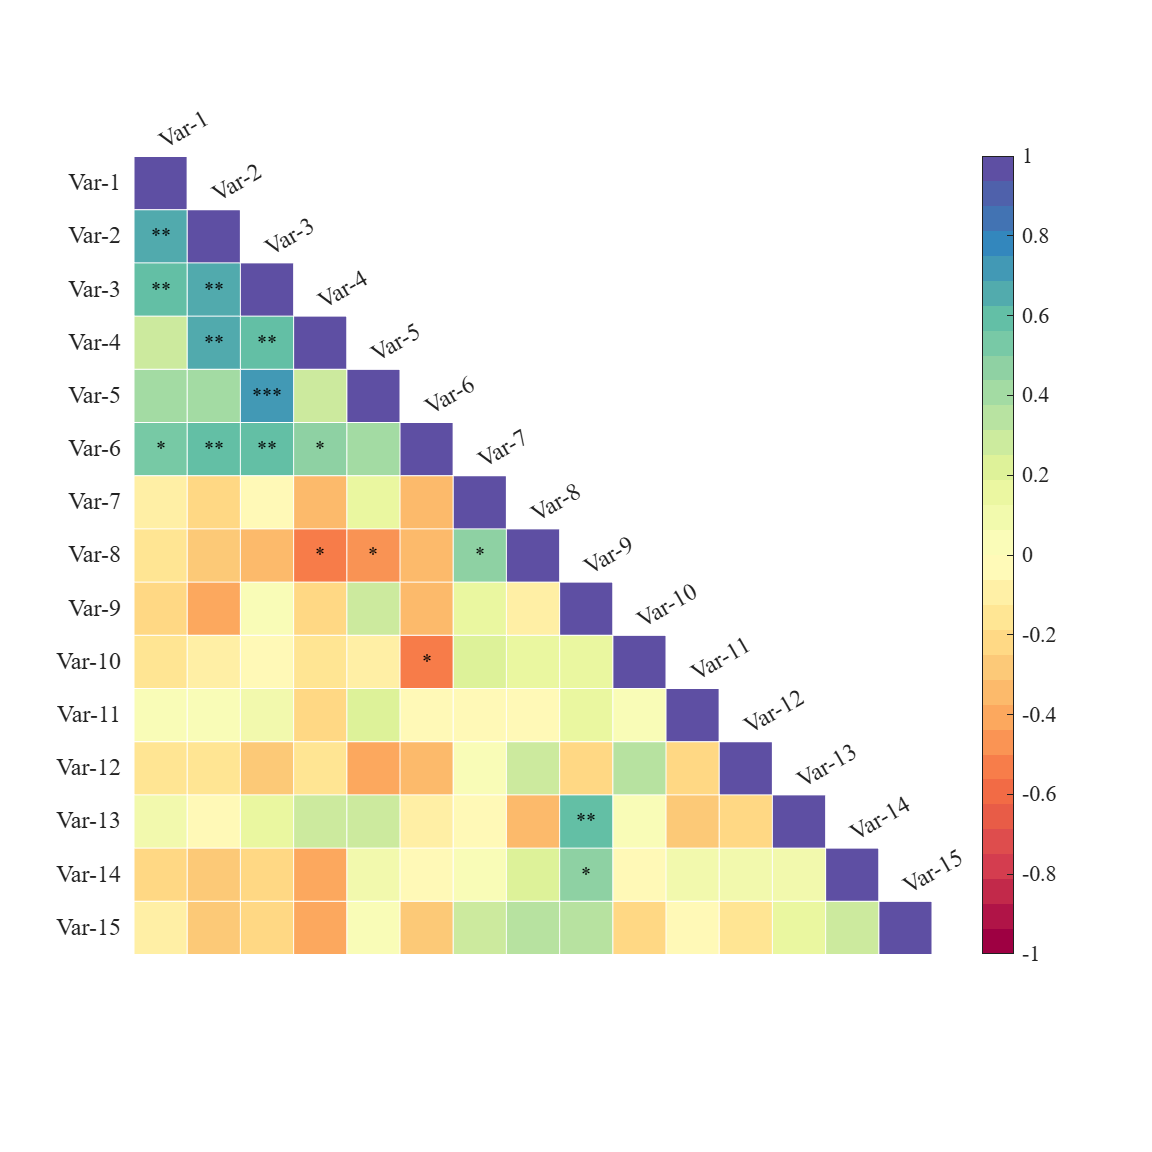

% Made up some data casually (随便捏造了点数据)
X = randn(20, 15) + [(linspace(-1,2.5,20)').*ones(1, 6), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 4)];
% Get the correlation matrix (求相关系数矩阵)
[Data, pval] = corr(X);

% create figure (图窗创建)
figure('Units','normalized', 'Position',[.1,.05,.45,.72])

% Draw heat map with texts (绘制有文本热图)
SHM12 = SHeatmap(Data, 'Format','sq').draw();
SHM12.setText().setType('tril');

% Displaying significance (显示显著性)
SHM12.showStars(pval, 'Levels', [0.05, 0.01, 0.001])

SHM12.showStars(pval, 'Levels', [0.05, 0.01, 0.001], 'CorrLabel','off')

## `13 Tiledlayout (Tiledlayout 布局)`

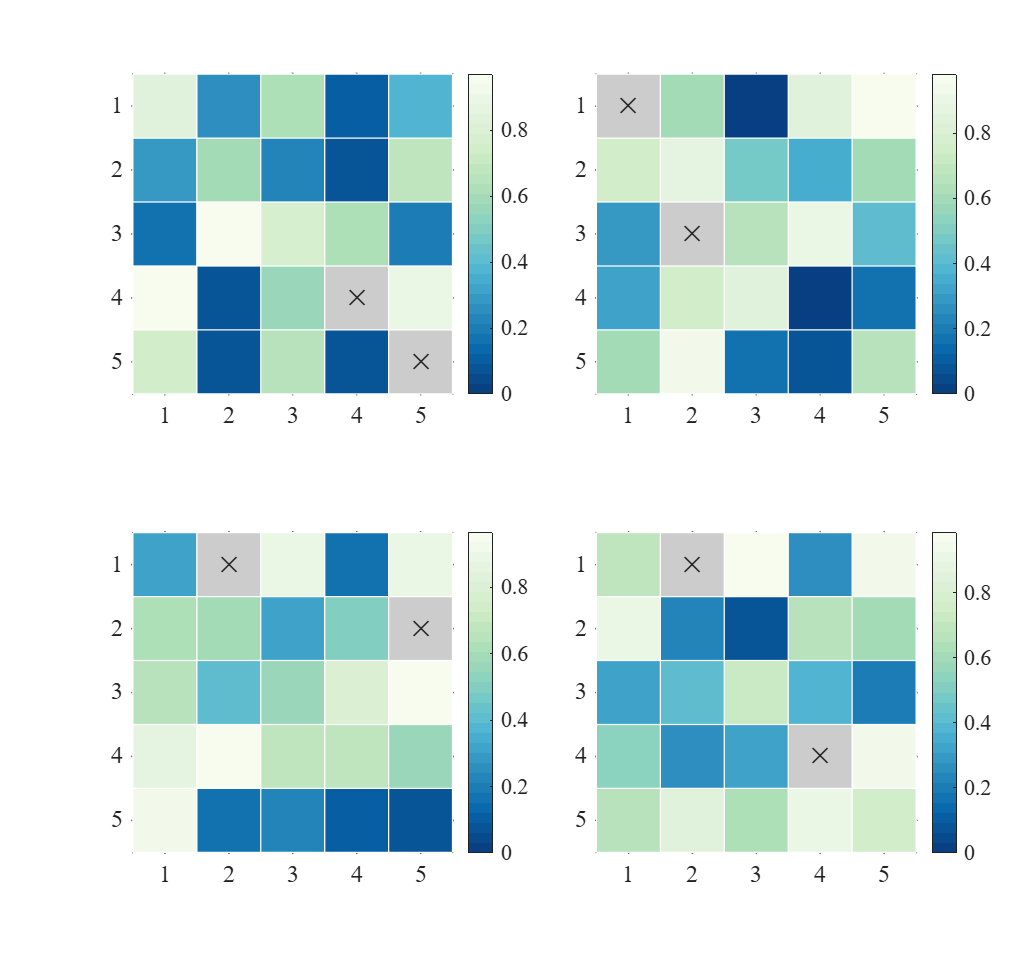

figure('Units','normalized', 'Position',[.2,.2,.4,.6])
tiledlayout(2, 2)

nexttile
Data = rand(5, 5);
Data(randi([1, 25], [2, 1])) = nan;
SHeatmap(Data, 'Format','sq').draw();


nexttile
Data = rand(5, 5);
Data(randi([1, 25], [2, 1])) = nan;
SHeatmap(Data, 'Format','sq').draw();


nexttile
Data = rand(5, 5);
Data(randi([1, 25], [2, 1])) = nan;
SHeatmap(Data, 'Format','sq').draw();


nexttile
Data = rand(5, 5);
Data(randi([1, 25], [2, 1])) = nan;
SHeatmap(Data, 'Format','sq').draw();

## `14 Heatmap with Mantel test links (带 Mantel 链接的热图)`

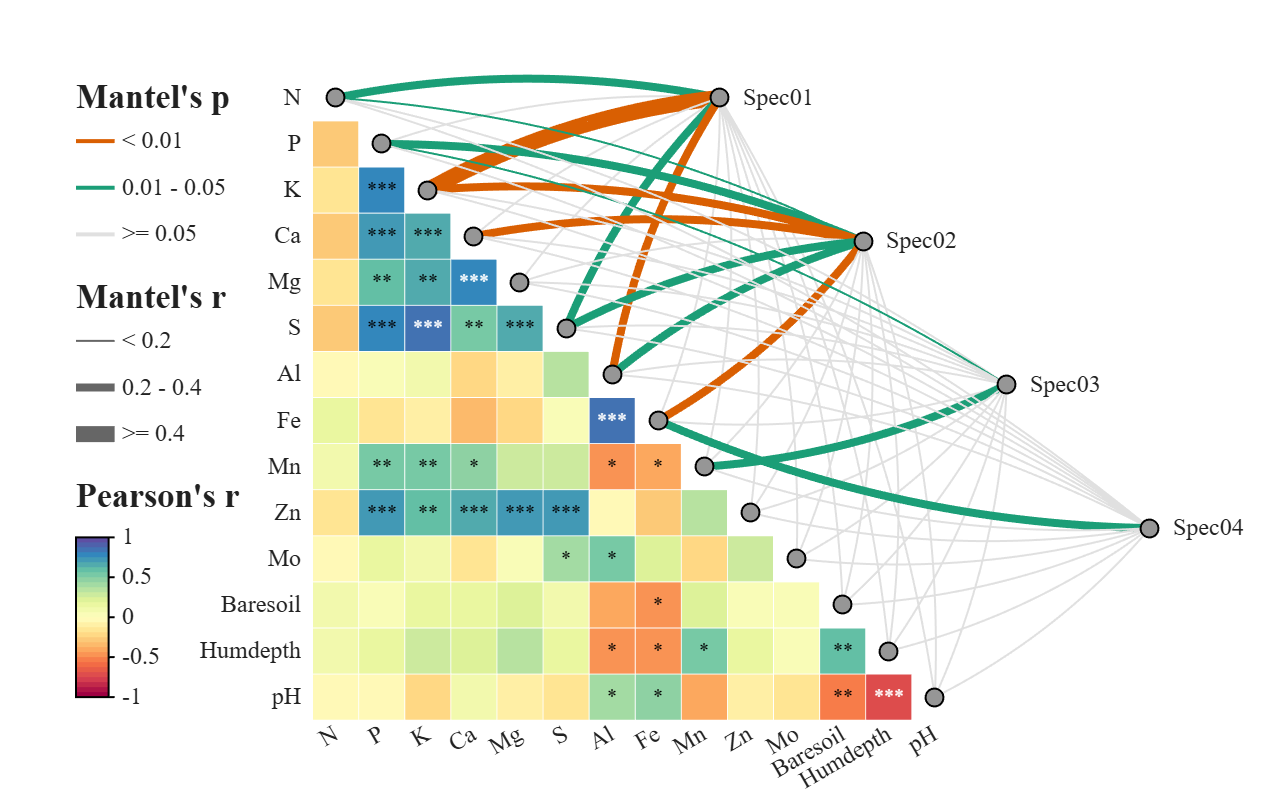

rng(7)
%% Load data (加载数据)
load('lichenData.mat')                      % Load pre-saved data package (加载预存的数据包)
Data1 = varechem.Variables;                 % Environmental matrix (环境因子矩阵)
Data2 = varespec.Variables;                 % Species composition matrix (物种组成矩阵)
labels = varechem.Properties.VariableNames; % Environmental variable names (环境变量名称)

% Define species groups: 44 columns into 4 groups (将44个物种列分为4组)
groupName = {'Spec01', 'Spec02', 'Spec03', 'Spec04'};
group = zeros(1, size(Data2, 2));
group(1:7) = 1;    % Group 1: columns 1-7 (第1组：列1-7)
group(8:18) = 2;   % Group 2: columns 8-18 (第2组：列8-18)
group(19:37) = 3;  % Group 3: columns 19-37 (第3组：列19-37)
group(38:44) = 4;  % Group 4: columns 38-44 (第4组：列38-44)

%% Figure and axes
fig = figure('Units','normalized', 'Position',[.05,.15,.72,.72]); 
ax = axes('Parent',fig, 'Position',[.06,.05,.88,.9]); 

%% Draw heatmap
[rho, pval] = corr(Data1);
objHM = SHeatmap(ax, rho, 'Format','sq').draw();
% Display significance stars: p < 0.05 *, p < 0.01 **, p < 0.001 *** 
objHM.setText().showStars(pval, 'Levels', [0.05, 0.01, 0.001], 'CorrLabel','off')
objHM.setVarName(labels).setType('linkl')

%% Draw mantel links
% Create Mantel link object with env data, species data and groups (创建Mantel链接对象，传入环境数据、物种数据及分组信息)
objML = SMantelLink(ax, Data1, Data2, 'Group',group);
objML.GroupName = groupName;          % Set group names (设置组名)
objML.LegendLocation = 'west';        % Place legend on the left (图例置于左侧)
objML.Layout = 'triu';                % Links placed in upper triangle (链接采用上三角布局)
objML.draw() 

### `14.2 Heatmap with Mantel test links - tril layout (链接在左下方)`

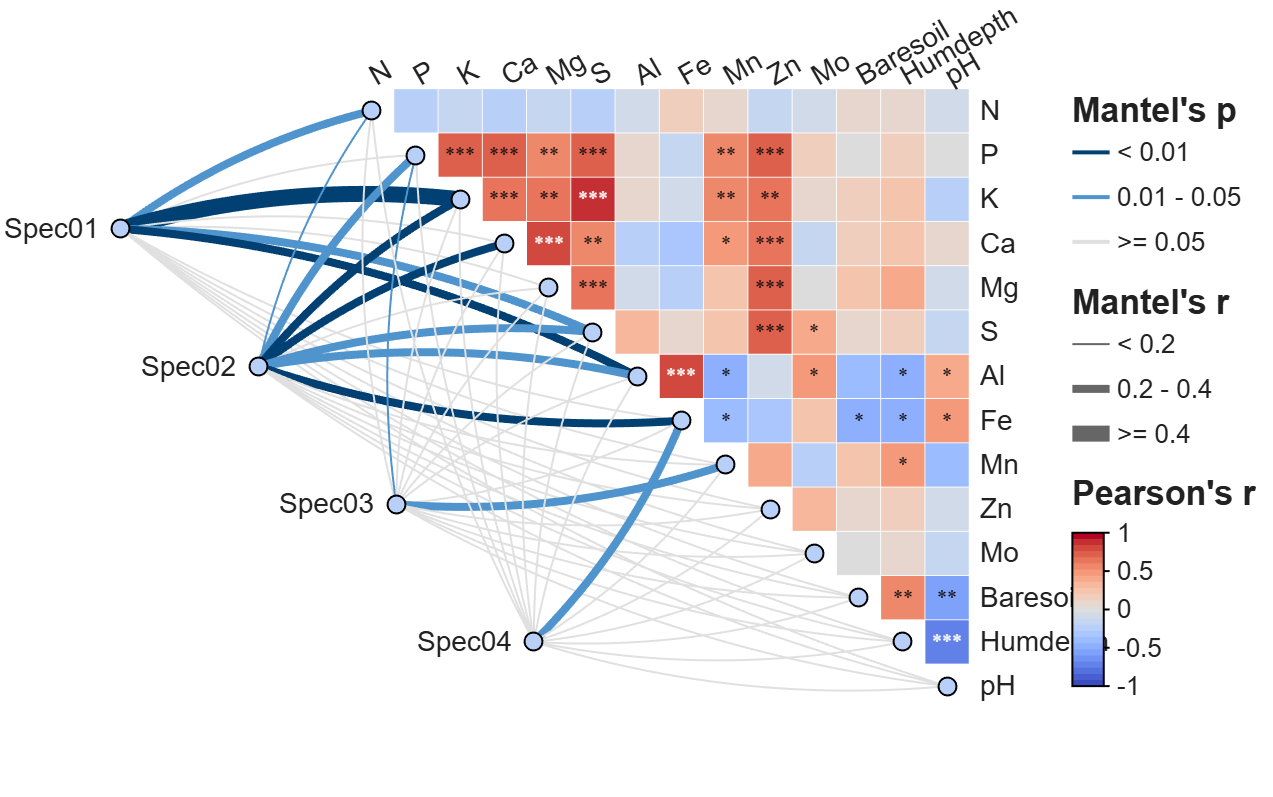

rng(7)
%% Load data
load('lichenData.mat')
Data1 = varechem.Variables;
Data2 = varespec.Variables;
labels = varechem.Properties.VariableNames;

groupName = {'Spec01', 'Spec02', 'Spec03', 'Spec04'};
group = zeros(1, size(Data2, 2));
group(1:7) = 1; 
group(8:18) = 2;
group(19:37) = 3;
group(38:44) = 4;

%% Figure and axes
fig = figure('Units','normalized', 'Position',[.05,.15,.72,.72]); 
ax = axes('Parent',fig, 'Position',[.06,.05,.88,.9]); 

%% Draw heatmap
[rho, pval] = corr(Data1);
objHM = SHeatmap(ax, rho, 'Format','sq').draw().setVarName(labels).setType('linku');
objHM.setText().showStars(pval, 'Levels',[0.05, 0.01, 0.001], 'CorrLabel','off')

% Apply a custom colormap with 25 colors (应用自定义 25 色 colormap)
colormap(slanCM(102, 25))
% Adjust font properties for labels (调整标签字体)
set([objHM.rowLabelHdl, objHM.colLabelHdl], 'FontSize',14, 'FontName','Helvetica')


%% Draw mantel links
objML = SMantelLink(ax, Data1, Data2, 'Group',group);
objML.GroupName = groupName;
objML.Layout = 'tril';
% Customize colors (自定义颜色)
objML.PColor = [0,64,115; 79,148,204; 224,224,224]./255;
objML.NodeColor1 = [184,207,248]./255;
objML.NodeColor2 = [184,207,248]./255;
objML.draw()

% Adjust legend and group label fonts (调整图例和组标签字体)
set(objML.legendTitleHdl, 'FontName','Helvetica')
set(objML.legendTickLabelHdl, 'FontSize',13, 'FontName','Helvetica')
set(objML.groupLabelHdl, 'FontSize',14, 'FontName','Helvetica')

## 15 GroupSep (分组间隙)

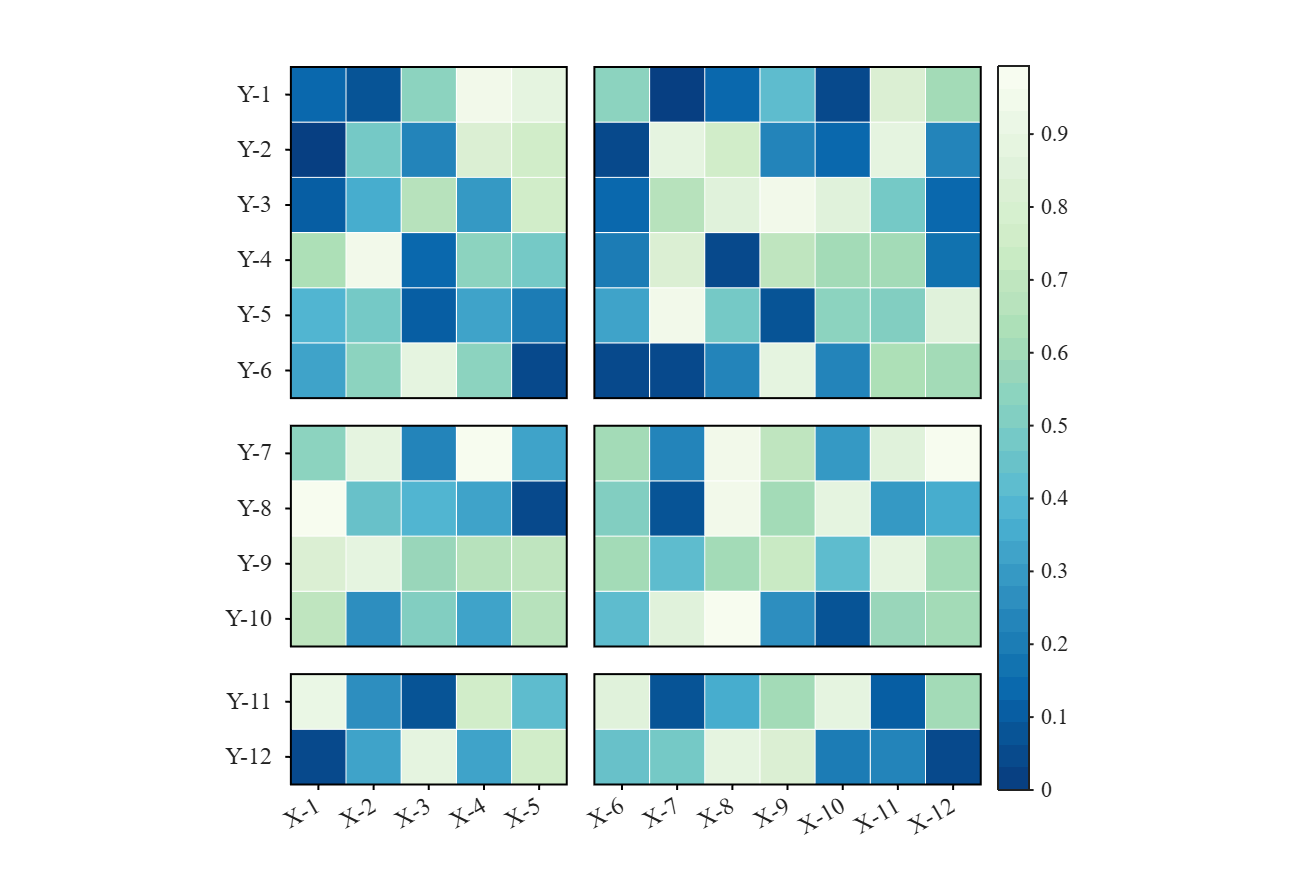

figure()
Data = rand(12, 12);
SHM = SHeatmap(Data, 'Format','sq');
SHM.RowName = {'Y-1','Y-2','Y-3','Y-4','Y-5','Y-6','Y-7','Y-8','Y-9','Y-10','Y-11','Y-12'};
SHM.ColName = {'X-1','X-2','X-3','X-4','X-5','X-6','X-7','X-8','X-9','X-10','X-11','X-12'};
SHM.RowGroup = [1,1,1,1,1,1, 2,2,2,2, 3,3];
SHM.ColGroup = [1,1,1,1,1, 2,2,2,2,2,2,2];
SHM.draw().setFrame()

### 15.2 Group Sep with non-square matrix (分组间隙与非方阵)

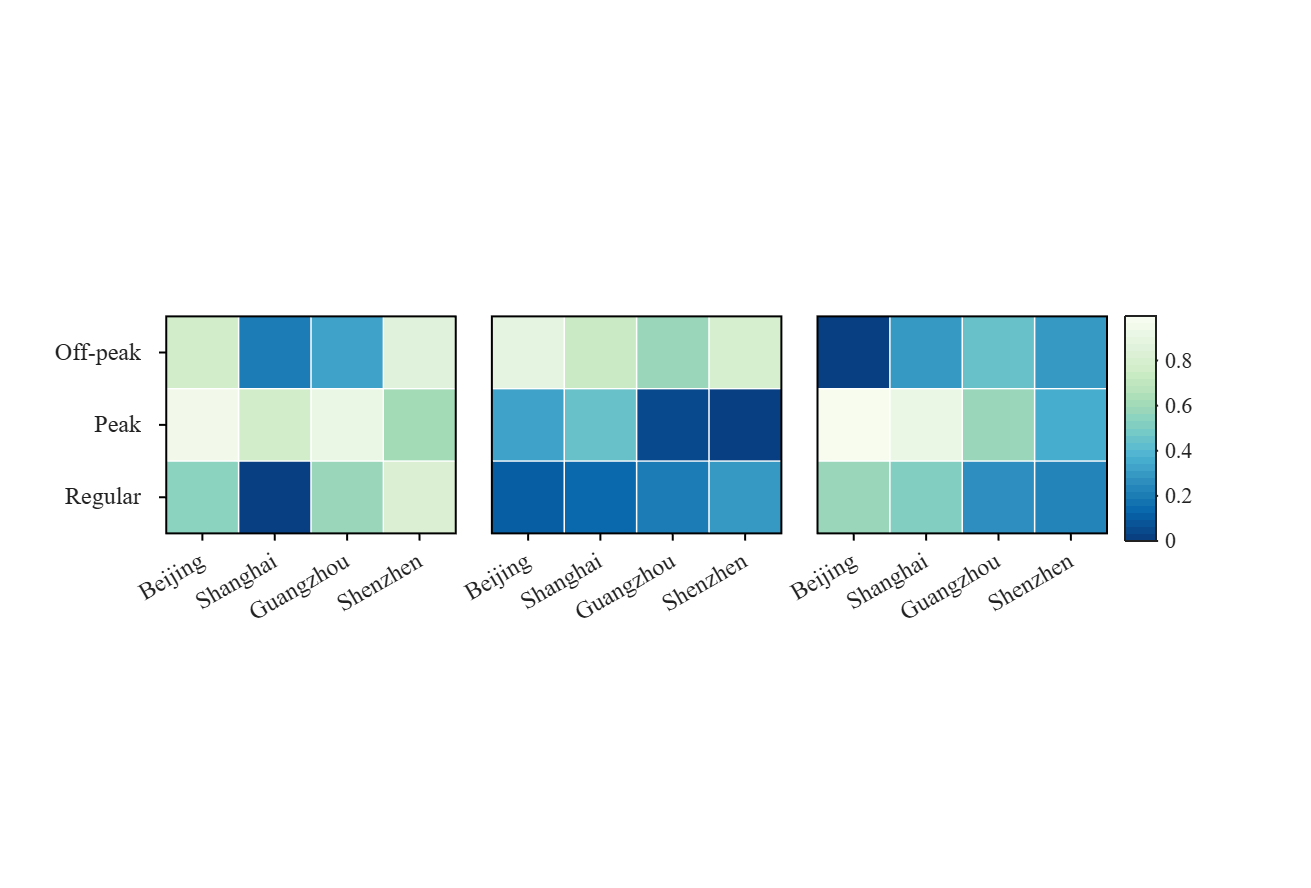

figure()
Data = rand(3, 12);
SHM = SHeatmap(Data, 'Format','sq');
SHM.RowName = {'Off-peak', 'Peak', 'Regular'};
SHM.ColName = {'Beijing', 'Shanghai', 'Guangzhou', 'Shenzhen'};
SHM.ColGroup = [1,1,1,1, 2,2,2,2, 3,3,3,3];
SHM.draw().setFrame()

### 15.3 Group Sep with triangular heatmap (分组间隙与三角热图)

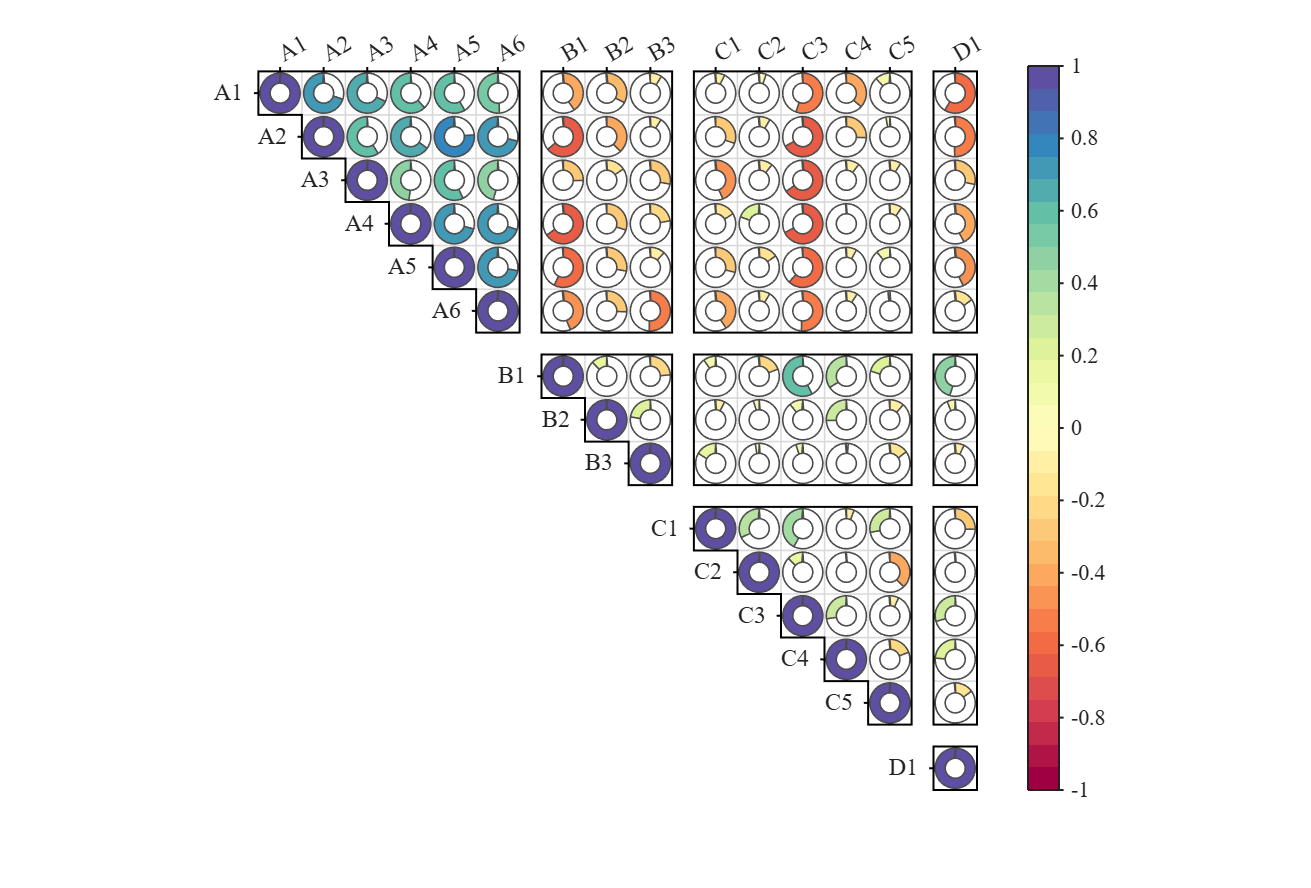

% Made up some data casually (随便捏造了点数据)
X = randn(20, 15) + [(linspace(-1,2.5,20)').*ones(1, 6), ...
    (linspace(.5,-.7,20)').*ones(1, 3), ...
    (linspace(.9,-.2,20)').*ones(1, 5), ...
    linspace(1.9,-.2,20)'];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X);

figure()
SHM = SHeatmap(Data, 'Format','donut');
SHM.RowGroup = [1,1,1,1,1,1, 2,2,2, 3,3,3,3,3, 4];
SHM.ColGroup = [1,1,1,1,1,1, 2,2,2, 3,3,3,3,3, 4];
SHM.VarName = {'A1','A2','A3','A4','A5','A6', 'B1','B2','B3', 'C1','C2','C3','C4','C5', 'D1'};
SHM.draw().setType('triu').setFrame()

### 15.4 Group Sep with group block (分组间隙与分组方块)

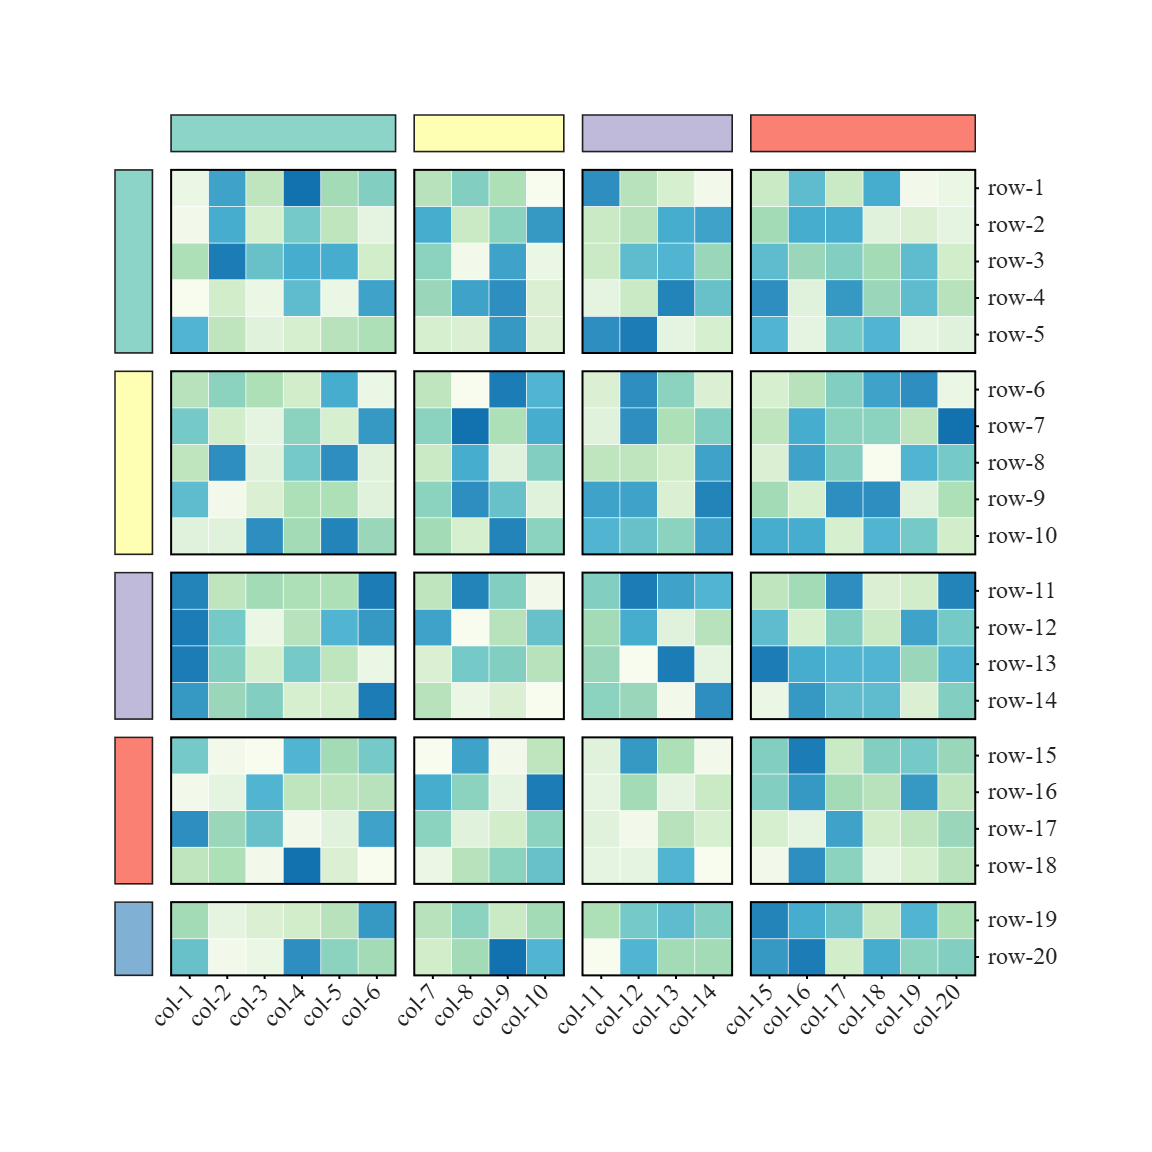

% Made up some data casually (随便捏造了点数据)
rowGroup = [1,1,1,1,1,2,2,2,2,2,3,3,3,3,4,4,4,4,5,5];
colGroup = [1,1,1,1,1,1,2,2,2,2,3,3,3,3,4,4,4,4,4,4];
rowName = compose('row-%d', 1:20);
colName = compose('col-%d', 1:20);
Data = rand(20, 20);

% create figure (图窗创建)
fig = figure('Units','normalized', 'Position',[.1,.05,.45,.72]);
ax = axes('Parent',fig, 'Position',[.1,.15,.75,.75]);

SClusterBlock(rowGroup, 'Orientation','left', 'Parent',ax, 'Group',rowGroup); % Draw the left Block (绘制左侧分组方块)
SClusterBlock(colGroup, 'Orientation','top' , 'Parent',ax, 'Group',colGroup); % Draw the top  Block (绘制顶部分组方块)
% Draw heatmap (绘制热图)
SHM = SHeatmap(Data, 'Format','sq', 'Parent',ax, 'RowGroup',rowGroup, 'ColGroup',colGroup).draw();
SHM.setRowLabelLocation('right').setColName(colName)
SHM.setColLabelLocation('bottom').setRowName(rowName)
SHM.setColLabel('Rotation',45).setFrame()

colorbar(ax, 'off');
clim(ax, [-.2, 1])
axis(ax, 'tight')
ax.DataAspectRatioMode = 'auto';

### 15.5 Group Sep with multilayer grouping block (分组间隙与多层分组方块)

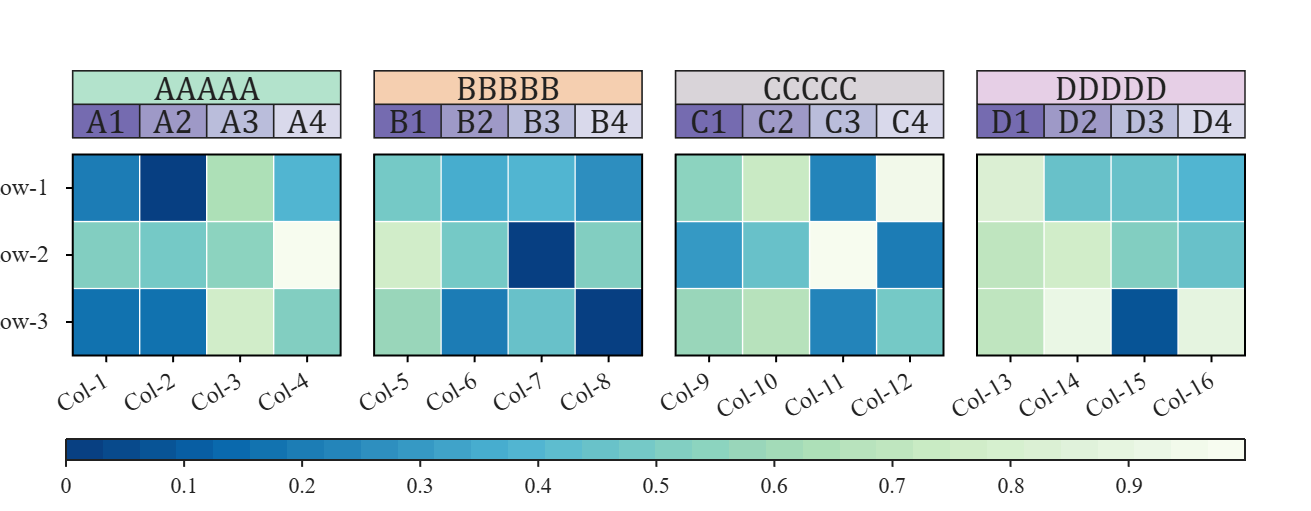

Data = rand(3, 16);
Class1 = [1,1,1,1, 2,2,2,2, 3,3,3,3, 4,4,4,4];
Class2 = [1,2,3,4, 1,2,3,4, 1,2,3,4, 1,2,3,4];
ClassName1 = {'AAAAA','BBBBB','CCCCC','DDDDD'};
ClassName2 = {'A1','A2','A3','A4','B1','B2','B3','B4','C1','C2','C3','C4','D1','D2','D3','D4'};
% Color (配色)
CList1 = [.70,.89,.80; .96,.81,.69; .85,.83,.85; .90,.81,.90];
CList2 = [.46,.42,.69; .62,.60,.78; .73,.74,.86; .85,.85,.92];

% create figure and axes (图窗及坐标区域创建)
fig = figure('Units','normalized', 'Position',[.05,.15,.72,.45]);
ax = axes('Parent',fig, 'Position',[.05,.15,.9,.85]);
% Draw Heatmap
SHM = SHeatmap(Data, 'Format','sq', 'Parent',ax, 'ColGroup',Class1);
SHM.RowName = compose('Row-%d', 1:3);
SHM.ColName = compose('Col-%d', 1:16);
SHM.draw().setFrame();
% Draw Block
[X1, Y1] = SClusterBlock(Class1, 'Orientation','top', 'BasePos',-.25, 'Height',.5, 'ColorList',CList1, 'Parent',ax, 'Group',Class1);
[X2, Y2] = SClusterBlock(Class2, 'Orientation','top', 'BasePos',.25 , 'Height',.5, 'ColorList',CList2, 'Parent',ax, 'Group',Class1);
% text
textProp = {'FontSize',17, 'HorizontalAlignment','center', 'FontName','Cambria'};
for i = 1:length(X1), text(ax, X1(i), Y1(i), ClassName1{i}, textProp{:}); end
for i = 1:length(X2), text(ax, X2(i), Y2(i), ClassName2{i}, textProp{:}); end

SHM.Colorbar.Location = 'southoutside';
SHM.Colorbar.Position = [.05, .1, .9, .04];

### 15.6 Group Sep with Tree (分组间隙与树状图)

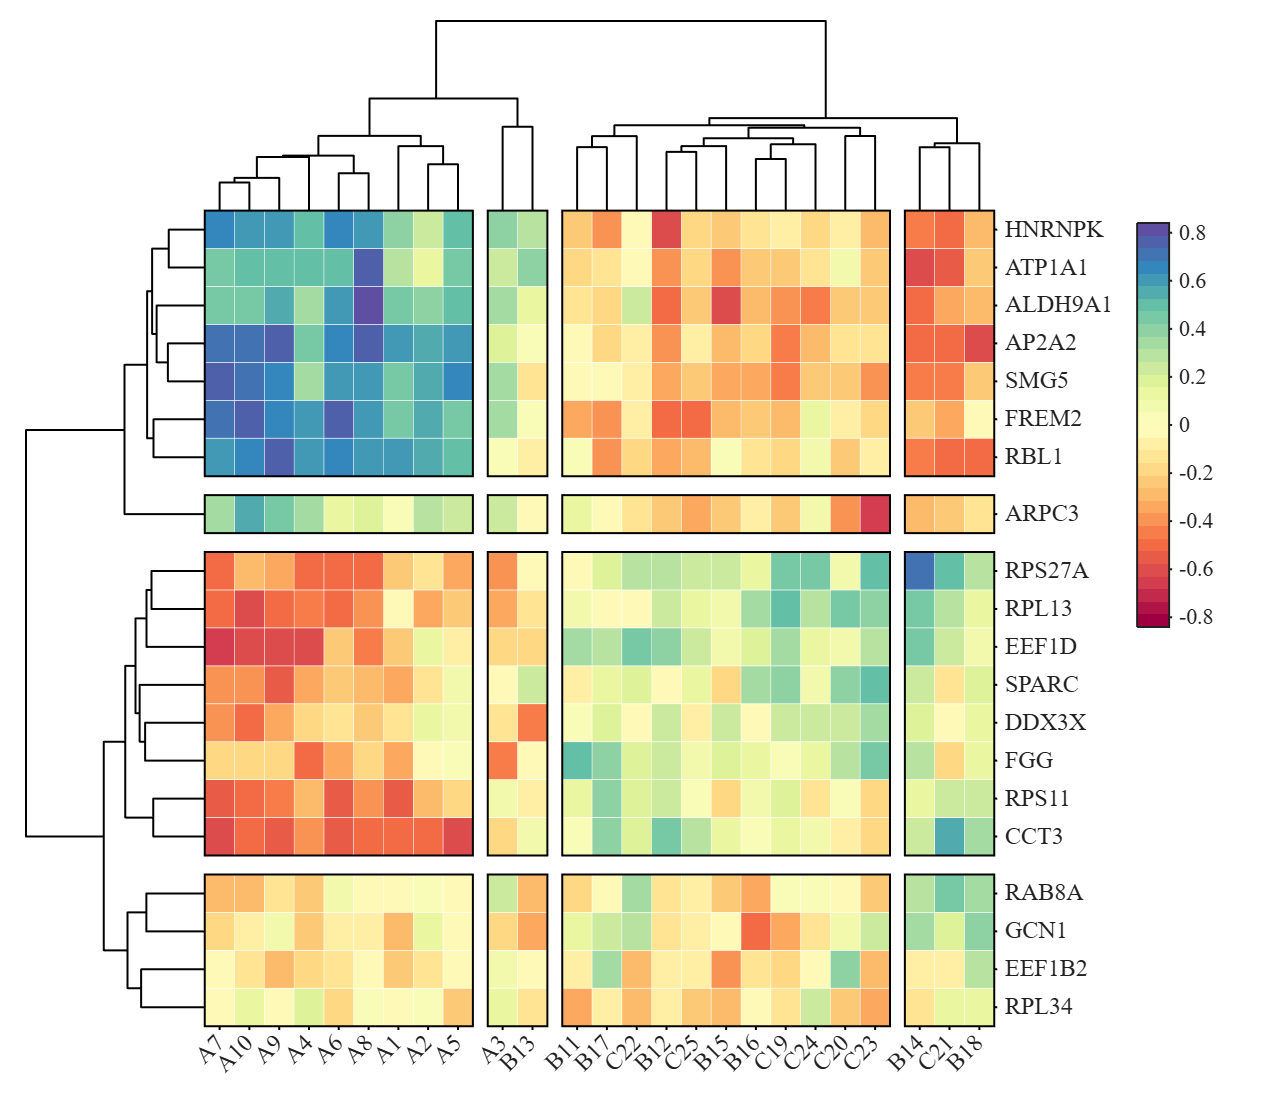

rng(1)
% Made up some data casually (随便捏造了点数据)
X1 = randn(20, 20) + [(linspace(-1,2.5,20)').*ones(1,  8), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 7)];
X2 = randn(20, 25) + [(linspace(-1,2.5,20)').*ones(1, 10), (linspace(.5,-.7,20)').*ones(1, 8), (linspace(.9,-.2,20)').*ones(1, 7)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X1, X2);
% rowName and colName
rowName = {'FREM2','ALDH9A1','RBL1','AP2A2','HNRNPK','ATP1A1','ARPC3','SMG5','RPS27A',...
    'RAB8A','SPARC','DDX3X','EEF1D','EEF1B2','RPS11','RPL13','RPL34','GCN1','FGG','CCT3'};
colName = {'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10','B11','B12','B13',...
    'B14','B15','B16','B17','B18','C19','C20','C21','C22','C23','C24','C25'};

fig = figure('Units','normalized', 'Position',[.1,.05,.5,.7]);
ax = axes('Parent',fig, 'Position',[.02,.08,.76,.9]);

[orderL, objL] = SDendrogram(Data, 'Orientation','left', 'Parent',ax, 'BasePos',.5, 'Height',6, 'MaxClust',4, 'GroupSep',.5);  % Draw the left dendrogram (绘制左侧树状图)
[orderT, objT] = SDendrogram(Data, 'Orientation','top' , 'Parent',ax, 'BasePos',.5, 'Height',5, 'MaxClust',4, 'GroupSep',.5);  % Draw the top  dendrogram (绘制顶部树状图)
% Exchange data order (交换数据顺序)
Data = Data(orderL, orderT);
% Draw heatmap (绘制热图)
SHM = SHeatmap(Data, 'Format','sq', 'Parent',ax, 'RowGroup',objL.Group, 'ColGroup',objT.Group).draw();
SHM.setRowLabelLocation('right').setColName(colName(orderT))
SHM.setColLabelLocation('bottom').setRowName(rowName(orderL))
SHM.setColLabel('Rotation',45).setFrame()
% Draw colorbar (绘制颜色条)
axis(ax, 'tight')
ax.DataAspectRatioMode = 'auto';
yn = size(Data, 1); yh = .9.*yn./(yn + 5) + .08;
SHM.Colorbar.Position = [.89, yh - .36, .025, .36];

### 15.7 Group Sep with Tree and Group block (分组间隙与树状图及分组方块)

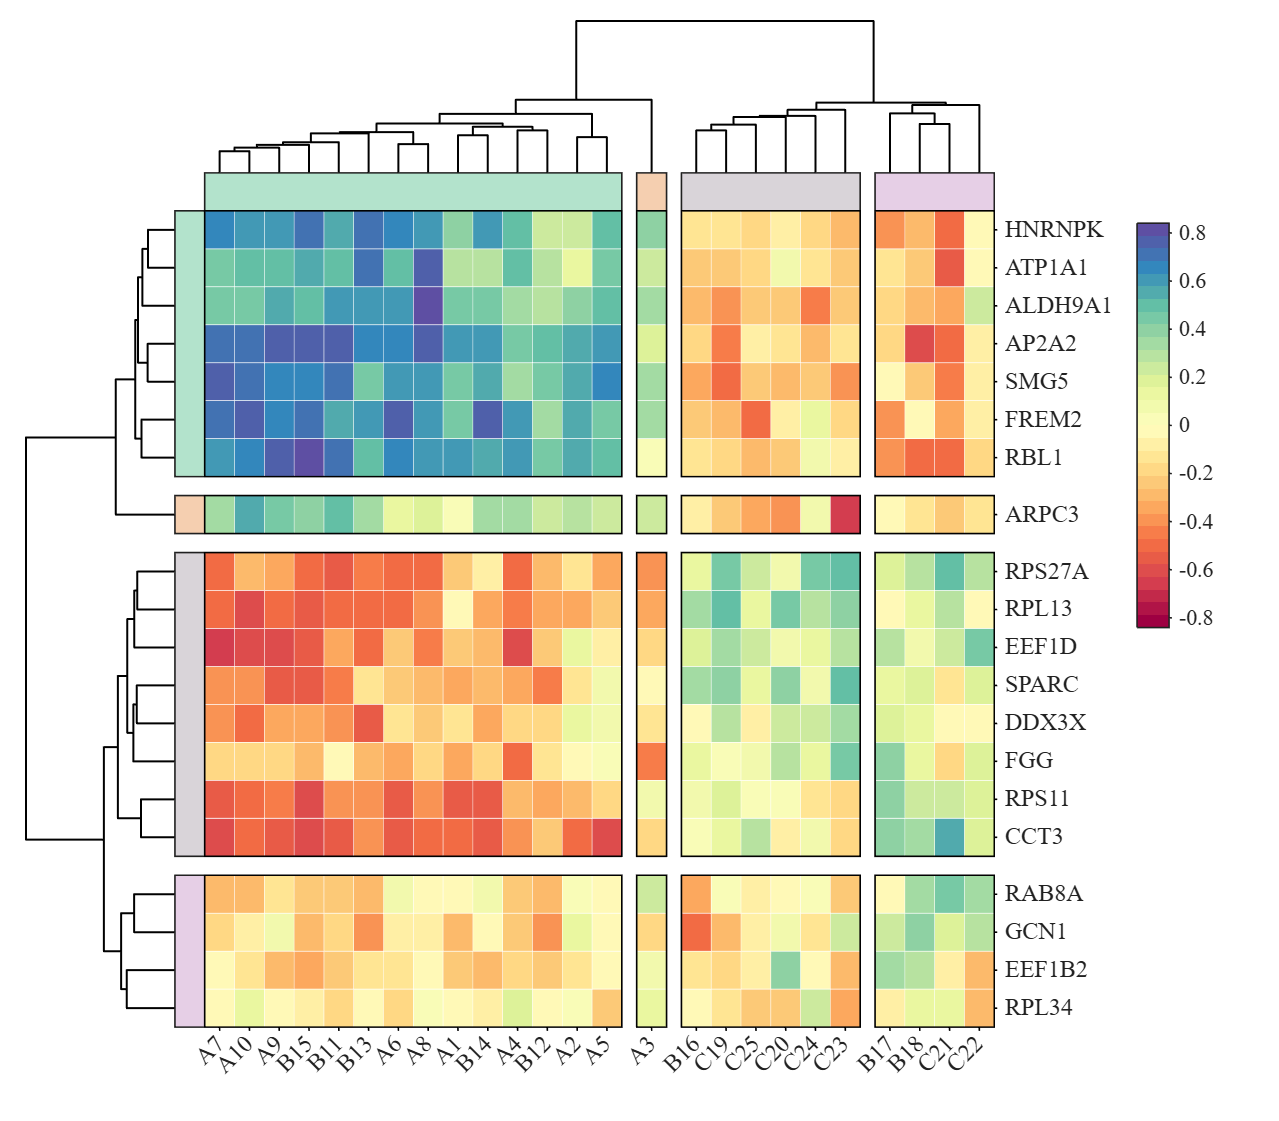

rng(1)
% Made up some data casually (随便捏造了点数据)
X1 = randn(20, 20) + [(linspace(-1,2.5,20)').*ones(1,  8), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 7)];
X2 = randn(20, 25) + [(linspace(-1,2.5,20)').*ones(1, 15), (linspace(.5,-.7,20)').*ones(1, 5), (linspace(.9,-.2,20)').*ones(1, 5)];
% Get the correlation matrix (求相关系数矩阵)
Data = corr(X1, X2);
% rowName and colName
rowName = {'FREM2','ALDH9A1','RBL1','AP2A2','HNRNPK','ATP1A1','ARPC3','SMG5','RPS27A',...
    'RAB8A','SPARC','DDX3X','EEF1D','EEF1B2','RPS11','RPL13','RPL34','GCN1','FGG','CCT3'};
colName = {'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10','B11','B12','B13',...
    'B14','B15','B16','B17','B18','C19','C20','C21','C22','C23','C24','C25'};

CList = [.70,.89,.80; .96,.81,.69; .85,.83,.85; .90,.81,.90];

fig = figure('Units','normalized', 'Position',[.1,.05,.5,.7]);
ax = axes('Parent',fig, 'Position',[.02,.08,.76,.9]);
% Draw tree and block (绘制树状图及分组方块)
[orderL, objL] = SDendrogram(Data, 'Orientation','left', 'Parent',ax, 'BasePos',-.5, 'Height',5, 'MaxClust',4, 'GroupSep',.5);  % Draw the left dendrogram (绘制左侧树状图)
[orderT, objT] = SDendrogram(Data, 'Orientation','top' , 'Parent',ax, 'BasePos',-.5, 'Height',4, 'MaxClust',4, 'GroupSep',.5);  % Draw the top  dendrogram (绘制顶部树状图)
Data = Data(orderL, orderT);  % Exchange data order (交换数据顺序)
SClusterBlock(objL.Group, 'ColorList',CList ,'Orientation','left', 'Parent',ax, 'BasePos',.5, 'Group',objL.Group); % Draw the left Block (绘制左侧分组方块)
SClusterBlock(objT.Group, 'ColorList',CList, 'Orientation','top' , 'Parent',ax, 'BasePos',.5, 'Group',objT.Group); % Draw the top  Block (绘制顶部分组方块)
% Draw heatmap (绘制热图)
SHM = SHeatmap(Data, 'Format','sq', 'Parent',ax, 'RowGroup',objL.Group, 'ColGroup',objT.Group).draw();
SHM.setRowLabelLocation('right').setColName(colName(orderT))
SHM.setColLabelLocation('bottom').setRowName(rowName(orderL))
SHM.setColLabel('Rotation',45).setFrame('LineWidth',.8)
% Draw colorbar (绘制颜色条)
axis(ax, 'tight')
ax.DataAspectRatioMode = 'auto';
yn = size(Data, 1); yh = .9.*yn./(yn + 5) + .08;
SHM.Colorbar.Position = [.89, yh - .36, .025, .36];